# Resource Prioritizing Recommandation for Hurricane Harvey

by WR

## Background and Scope

### Import the Data

Table `stormData` is created with `State, Month, Event_Type, CZ_Name, ...` 16 variables and 57005 observations. In the 2017 storm events data set, Harvey related events are reported beginning August 17th and end September 3rd as the system moved north and east across the United States. Therefore, to study the aftermath of Harvey, we select events that happened after August 17th and ended September 3rd.

stormData = importStormEvents("StormEvents_2017_finalProject.csv");
stormData = stormData(stormData.Begin_Date_Time >= '2017-08-17 00:00:00',:);
stormData = stormData(stormData.End_Date_Time <= '2017-09-04 00:00:00',:);

### Two States Most Impacted by Harvey

The two states most impacted by Hurricane Harvey in terms of total Property Cost are **Texas **and** Louisiana**. More details about the Harvey can be found in [NOAA Harvey Report](https://www.nhc.noaa.gov/data/tcr/AL092017_Harvey.pdf).

stormData.Property_Cost(ismissing(stormData.Property_Cost)) = 0;
stormData.Crop_Cost(ismissing(stormData.Crop_Cost)) = 0;
stormData.Total_Cost = stormData.Property_Cost + stormData.Crop_Cost;
propertyCostByState = groupsummary(stormData,"State","sum","Property_Cost");

propertyCostByState = sortrows(propertyCostByState,'sum_Property_Cost','descend');
mostImpactedState = propertyCostByState.State([1,2],1)

mostImpactedState = 2×1 categorical array
     TEXAS 
     LOUISIANA 


### Table of Events for Two Most Impacted States

Preview first 8 rows of events that include only the two most affected states.

twoStatesData = stormData(stormData.State=="TEXAS"|stormData.State=="LOUISIANA",:);
head(twoStatesData)

ans = 8×17 table
    State    Month        Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Deaths_Direct    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      Episode_Narrative

## Visualizations

### Figure of Event Types

This histogram shows the type and number of occurances for events related to Harvey in the two states in different colors.

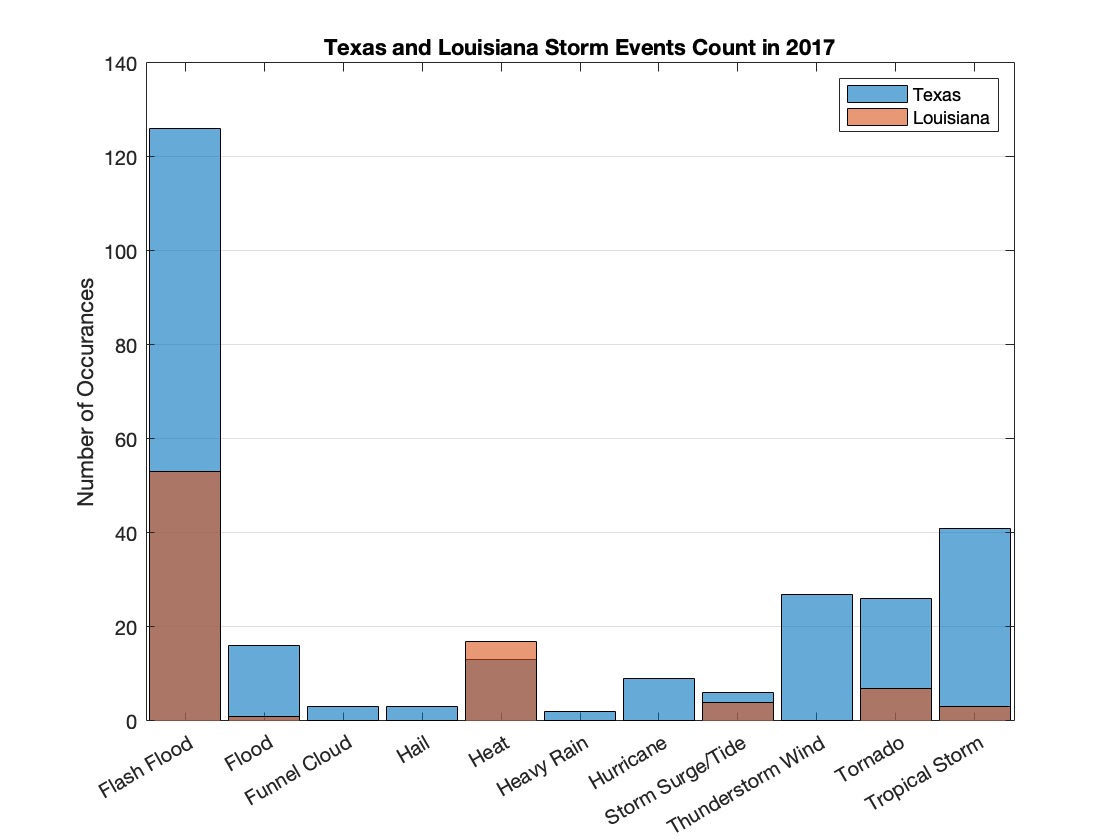

% Remove non-occurrance event categories
twoStatesEvent = twoStatesData;
twoStatesEvent.State = removecats(twoStatesEvent.State,{'ALABAMA','ALASKA','AMERICAN SAMOA','ARIZONA',...
    'ARKANSAS','ATLANTIC NORTH','ATLANTIC SOUTH','CALIFORNIA','COLORADO','CONNECTICUT','DELAWARE',...
    'DISTRICT OF COLUMBIA','E PACIFIC','GEORGIA','GUAM','GULF OF MEXICO','HAWAII','HAWAII WATERS',...
    'IDAHO','ILLINOIS','INDIANA','IOWA','KANSAS','KENTUCKY','LAKE ERIE','LAKE HURON','LAKE MICHIGAN',...
    'LAKE ONTARIO','LAKE ST CLAIR','LAKE SUPERIOR','FLORIDA','MAINE','MARYLAND','MASSACHUSETTS',...
    'MICHIGAN','MINNESOTA','MISSISSIPPI','MISSOURI','MONTANA','NEBRASKA','NEVADA','NEW HAMPSHIRE',...
    'NEW JERSEY','NEW MEXICO','NEW YORK','NORTH CAROLINA','NORTH DAKOTA','OHIO','OKLAHOMA','OREGON',...
    'PENNSYLVANIA','PUERTO RICO','RHODE ISLAND','SOUTH CAROLINA','SOUTH DAKOTA','ST LAWRENCE R',...
    'TENNESSEE','UTAH','VERMONT','VIRGIN ISLANDS','VIRGINIA','WASHINGTON','WEST VIRGINIA','WISCONSIN','WYOMING'});
twoStatesEvent.Event_Type = removecats(twoStatesEvent.Event_Type,{'Astronomical Low Tide','Avalanche',...
    'Blizzard','Coastal Flood','Cold/Wind Chill','Debris Flow','Dense Fog','Dense Smoke','Drought',...
    'Dust Devil','Dust Storm','Excessive Heat','Extreme Cold/Wind Chill','Freezing Fog','Frost/Freeze',...
    'Heavy Snow','High Surf','High Wind','Ice Storm','Lake-Effect Snow','Lakeshore Flood','Lightning',...
    'Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind',...
    'Marine Tropical Depression','Marine Tropical Storm','Rip Current','Sleet','Sneakerwave','Strong Wind',...
    'Tropical Depression','Waterspout','Wildfire','Winter Storm','Winter Weather'});

histogram(twoStatesEvent.Event_Type(twoStatesEvent.State=="TEXAS"))
hold on
histogram(twoStatesEvent.Event_Type(twoStatesEvent.State=="LOUISIANA"))
hold off

legend({'Texas','Louisiana'})
title('Texas and Louisiana Storm Events Count in 2017')
ylabel('Number of Occurances')
set(gca,'XGrid','off','YGrid','on')

### Figure of Event Locations

This geographic plot shows the location of events in the two states. The size of the bubble is depend on its total cost.

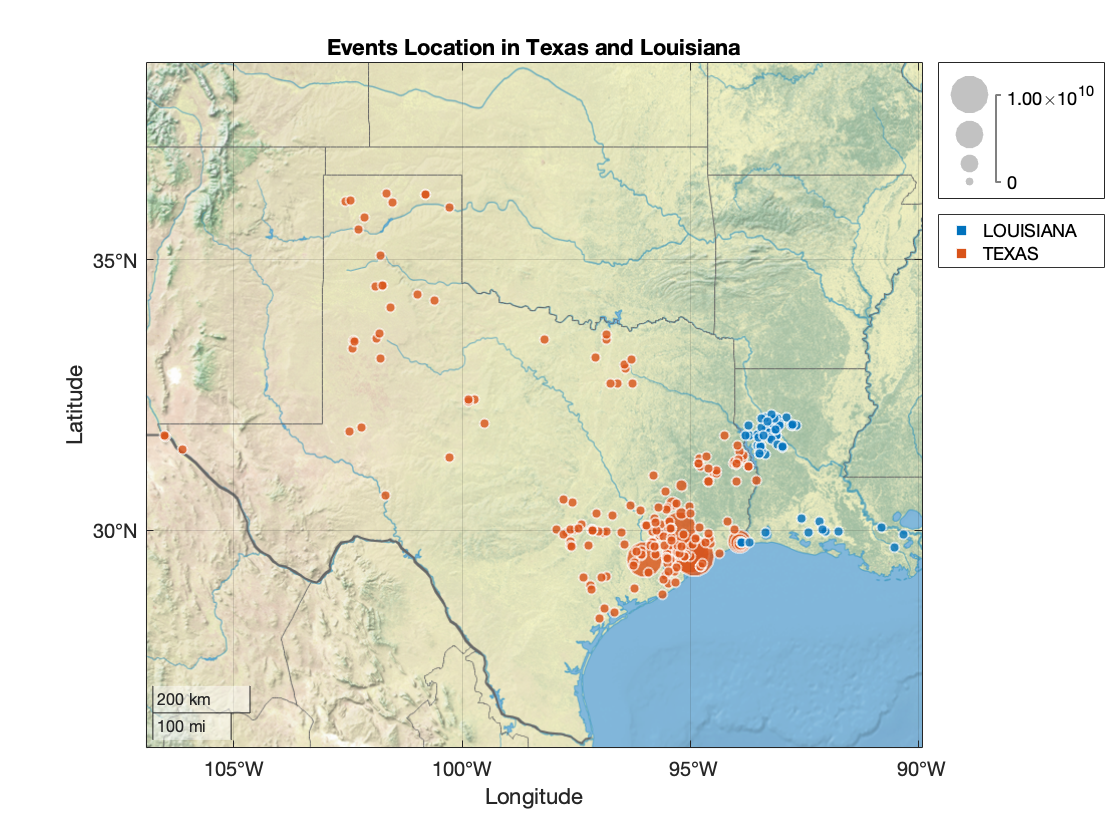

geobubble(twoStatesEvent.Begin_Lat,twoStatesEvent.Begin_Lon,twoStatesEvent.Total_Cost,twoStatesEvent.State);
geobasemap('landcover')
legend show
title('Events Location in Texas and Louisiana')

## Analysis

In this part, we explore the data to find the counties most affected by Hurricane Harvey. 

### Three Counties with Most Events in Texas

As displayed, three counties in Texas with most events are **Harris**, **Galveston** and **Fort Bend**. Remove semicolon in the second line to see the whole county list.

texasData = twoStatesEvent(twoStatesEvent.State=="TEXAS",:);
texasEvents = groupsummary(texasData,"CZ_Name");
texasEvents = sortrows(texasEvents,'GroupCount','descend');
texasCounty = texasEvents.CZ_Name(1:3,1)

texasCounty = 3×1 categorical array
     HARRIS 
     GALVESTON 
     FORT BEND 


### Three Counties with Most Events in Louisiana

As displayed, three counties in Louisiana with most events are **Natchitoches**, **Sabine** and **Red River**. Remove semicolon in the second line to see the whole county list.

louisianaData = twoStatesEvent(twoStatesEvent.State=="LOUISIANA",:);
louisianaEvents = groupsummary(louisianaData,"CZ_Name");
louisianaEvents = sortrows(louisianaEvents,'GroupCount','descend');
louisianaCounty = louisianaEvents.CZ_Name(1:3,1)

louisianaCounty = 3×1 categorical array
     NATCHITOCHES 
     SABINE 
     RED RIVER 


### Three Counties with Highest Property Cost in Texas

The `texasCountyProp` table displays three counties in Texas with highest property cost in order: **Galveston**, **Fort** **Bend** and **Montgomery**. Property cost in dollar unit. Remove semicolon in the third line to see the whole county list.

texasProperty = groupsummary(texasData,"CZ_Name","sum","Property_Cost");
texasProperty = sortrows(texasProperty,'sum_Property_Cost','descend');
texasPosProperty = texasProperty(texasProperty.sum_Property_Cost >= 0.01,:);
% bar(texasPosProperty.sum_Property_Cost)
texasCountyProp = texasPosProperty(1:3,[1,3])

texasCountyProp = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    GALVESTON             2e+10    
    FORT BEND        1.6004e+10    
    MONTGOMERY          1.4e+10    


### Three Counties with Highest Property Cost in Louisiana

The `louisianaCountyProp` table displays three counties in Louisiana with highest property cost in order: **Calcasieu**,  **Beauregard** and **Acadia**. Property cost in dollar unit. Remove semicolon in the third line to see the whole county list.

louisianaProperty = groupsummary(louisianaData,"CZ_Name","sum","Property_Cost");
louisianaProperty = sortrows(louisianaProperty,'sum_Property_Cost','descend');
louisianaPosProperty = louisianaProperty(louisianaProperty.sum_Property_Cost >= 0.01,:);
% bar(louisianaPosProperty.sum_Property_Cost)
louisianaCountyProp = louisianaPosProperty(1:3,[1,3])

louisianaCountyProp = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    CALCASIEU            6e+07     
    BEAUREGARD         1.5e+07     
    ACADIA               2e+05     


## Conclusions and Recommendations

From observations above, we find the two states most impacted by Harvey are Texas and Louisiana. We also analyzed three counties with most event and highest property cost in each state respectively. Thus, these two states are supposed to be our priority to allocate resources. 

Furthermore, we compare the level of property damage between top three counties within each state.

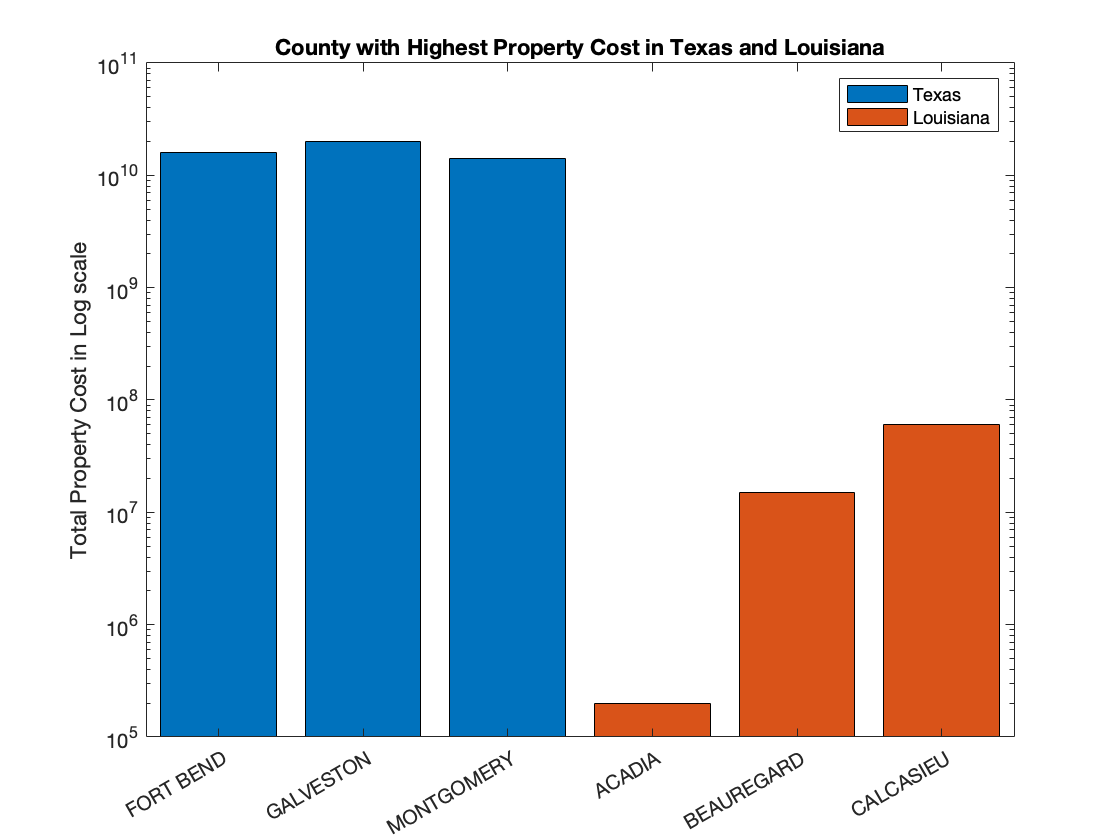

% texasCountyProp.CZ_Name = removecats(texasCountyProp.CZ_Name,{'5NM E OF FAIRPORT MI TO ROCK ISLAND PASSAGE','5NM E OF MACKINAC BRIDGE TO PRESQUE ISLE LIGHT MI INC BOIS BLANC ISLAND','ABBEVILLE','ABSAROKA MOUNTAINS','ABSAROKEE / BEARTOOTH MOUNTAINS','ACADIA','ACCOMACK','ADA','ADAIR','ADAMS','ADDISON','ADJUNTAS','ADMIRALTY INLET AREA','AGUADA','AGUADILLA','AGUAS BUENAS','AIBONITO','AIKEN','AITKIN','ALACHUA','ALAMANCE','ALAMEDA','ALASKA PENINSULA','ALBANY','ALBEMARLE','ALBUQUERQUE METRO AREA','ALCONA','ALCORN','ALEXANDER','ALEXANDRIA (C)','ALFALFA','ALGER','ALLAMAKEE','ALLEGAN','ALLEGANY','ALLEGHANY','ALLEGHENY','ALLEN','ALLENDALE','ALLIGATOR RIVER','ALPENA','ALTAMAHA SD TO FERNANDINA BEACH FL OUT 20NM','AMADOR','AMELIA','AMHERST','AMITE','ANASCO','ANCHORAGE MUNI TO BIRD CREEK','ANDERSON','ANDREW','ANDREWS','ANDROSCOGGIN','ANGELINA','ANIMAS RIVER BASIN','ANNE ARUNDEL','ANOKA','ANSON','ANTELOPE','ANTELOPE VALLEY','ANTRIM','APACHE','APALACHEE BAY OR COASTAL WATERS FROM KEATON BEACH TO OCHLOCKONEE RIVER FL OUT TO 20 NM','APALACHICOLA TO DESTIN FL 20 TO 60NM','APALACHICOLA TO DESTIN FL OUT 20NM','APPANOOSE','APPLE AND LUCERNE VALLEYS','APPLING','APPOMATTOX','ARANSAS','ARAPAHOE','ARCHER','ARCHULETA','ARECIBO','ARKANSAS','ARLINGTON','ARMSTRONG','AROOSTOOK','ARROYO','ARTHUR','ASCENSION','ASHE','ASHLAND','ASHLEY','ASHTABULA','ASHTABULA LAKESHORE','ASOTIN','ASSUMPTION','ATASCOSA','ATCHAFALAYA R TO INTRACOASTAL CITY LA 20 TO 60NM','ATCHAFALAYA R TO INTRACOASTAL CITY LA OUT 20NM','ATCHISON','ATHENS','ATKINSON','ATLANTIC','ATOKA','ATTALA','AUDRAIN','AUDUBON','AUGLAIZE','AUGUSTA','AURORA','AUSTIN','AUTAUGA','AVERY','AVON POINT TO WILLOWICK OH','AVOYELLES','BABOQUIVARI MOUNTAINS','BACA','BACON','BAILEY','BAKER','BALDWIN','BALDWIN CENTRAL','BALDWIN COASTAL','BALDWIN INLAND','BALDWIN PEN. & SELAWIK VALLEY','BALLARD','BALTIMORE','BALTIMORE CITY (C)','BAMBERG','BANDERA','BANKS','BANNER','BANNOCK','BARAGA','BARBER','BARBOUR','BARCELONETA','BARNES','BARNSTABLE','BARNWELL','BARRANQUITAS','BARREN','BARRON','BARROW','BARRY','BARTHOLOMEW','BARTON','BARTOW','BASTROP','BATES','BATH','BAXTER','BAY','BAYAMON','BAYFIELD','BAYLOR','BAYSIDE AND GULFSIDE FROM CRAIG KEY TO WEST END OF SEVEN MILE BRIDGE','BEADLE','BEAR LAKE','BEARTOOTH FOOTHILLS','BEAUFORT','BEAUREGARD','BEAVER','BEAVERHEAD','BECKER','BECKHAM','BEDFORD','BEE','BELAU','BELKNAP','BELL','BELLEVUE AND VICINITY','BELMONT','BELTRAMI','BEN HILL','BENEWAH','BENNETT','BENNINGTON','BENSON','BENT','BENT COUNTY','BENTON','BERGEN','BERKELEY','BERKS','BERKSHIRE','BERNALILLO','BERRIEN','BERTIE','BEXAR','BIBB','BIENVILLE','BIG AND LITTLE WOOD RIVER REGION','BIG BEND AREA','BIG HORN','BIG ISLAND INTERIOR','BIG ISLAND NORTH AND EAST','BIG ISLAND SUMMIT','BIG STONE','BIGHORN MOUNTAINS SOUTHEAST','BIGHORN MOUNTAINS WEST','BILLINGS','BINGHAM','BISCAYNE BAY','BITTERROOT / SAPPHIRE MOUNTAINS','BLACK HAWK','BLACK MESA AREA','BLACK RIVER TO ONTONAGON MI','BLACKFORD','BLADEN','BLAINE','BLAIR','BLANCO','BLAND','BLECKLEY','BLEDSOE','BLOCK ISLAND','BLOUNT','BLOUNT/SMOKY MOUNTAINS','BLUE EARTH','BLUE MOUNTAIN FOOTHILLS','BOISE','BOISE MOUNTAINS','BOLIVAR','BOLLINGER','BON HOMME','BOND','BONNER','BONNEVILLE','BOONE','BORDEN','BOSQUE','BOSSIER','BOTETOURT','BOTTINEAU','BOULDER','BOULDER & JEFFERSON COUNTIES BELOW 6000 FEET / W BROOMFIELD COUNTY','BOUNDARY','BOURBON','BOWIE','BOWMAN','BOX BUTTE','BOX ELDER','BOYD','BOYLE','BRACKEN','BRADFORD','BRADLEY','BRANCH','BRANTLEY','BRAXTON','BRAZORIA','BRAZOS','BREATHITT','BRECKINRIDGE','BREMER','BREMERTON AND VICINITY','BRETON SOUND','BREVARD','BREWSTER','BRISCOE','BRISTOL','BRISTOL (C)','BRISTOL BAY','BROADWATER','BRONX','BROOKE','BROOKINGS','BROOKS','BROOME','BROWARD','BROWN','BRULE','BRUNSWICK','BRYAN','BUCHANAN','BUCKINGHAM','BUCKS','BUENA VISTA','BUFFALO','BUFFALO FOOTHILLS','BULLITT','BULLOCH','BULLOCK','BUNCOMBE','BUREAU','BURKE','BURKE MOUNTAINS','BURLEIGH','BURLESON','BURLINGTON','BURNET','BURNETT','BURNEY BASIN/EASTERN SHASTA COUNTY','BURNS HARBOR TO MICHIGAN CITY IN','BURT','BUTLER','BUTTE','BUTTE / BLACKFOOT REGION','BUTTS','C & E ADAMS & ARAPAHOE COUNTIES','C & S WELD COUNTY','CABARRUS','CABELL','CABO ROJO','CACHE','CACHE VALLEY/IDAHO PORTION','CACHE VALLEY/UTAH','CADDO','CAGUAS','CALAVERAS','CALCASIEU','CALDWELL','CALDWELL MOUNTAINS','CALEDONIA','CALHOUN','CALLAHAN','CALLAWAY','CALLOWAY','CALUMET','CALVERT','CAMAS PRAIRIE','CAMBRIA','CAMDEN','CAMERON','CAMP','CAMPBELL','CAMUY','CANADIAN','CANDLER','CANNON','CANON CITY VICINITY / EASTERN FREMONT COUNTY','CANOVANAS','CANYON','CANYONLANDS / NATURAL BRIDGES','CAPE DECISION TO SALISBURY SOUND COASTAL AREA','CAPE FAIRWEATHER TO CAPE SUCKLING COASTAL AREA','CAPE GIRARDEAU','CAPE LOOKOUT TO SURF CITY NC FROM 20 TO 40 NM','CAPE MAY','CAPE SHOALWATER TO CASCADE HEAD...OUT TO 10 NM','CARBON','CARIBOU','CARIBOU HIGHLANDS','CARLISLE','CARLTON','CAROLINA','CAROLINE','CARQUINEZ STRAIT AND DELTA','CARROLL','CARSON','CARSON CITY (C)','CARTER','CARTERET','CARVER','CASCADE','CASCADE FOOTHILLS IN LANE COUNTY','CASCADE HEAD TO FLORENCE...OUT TO 10 NM','CASCADES IN LANE COUNTY','CASCADES OF PIERCE AND LEWIS COUNTIES','CASCADES OF SNOHOMISH AND KING COUNTIES','CASCADES OF WHATCOM AND SKAGIT COUNTIES','CASEY','CASPER MOUNTAIN','CASS','CASSIA','CASTLE COUNTRY','CASTRO','CASWELL','CATAHOULA','CATALINA AND SANTA BARBARA ISLANDS','CATANO','CATAWBA','CATOOSA','CATRON','CATTARAUGUS','CAVALIER','CAYEY','CAYUGA','CECIL','CEDAR','CEIBA','CENTRAL & EASTERN LAKE COUNTY','CENTRAL ALEUTIANS','CENTRAL AND EASTERN ALLEGANY','CENTRAL AND SE PHILLIPS','CENTRAL AND SOUTHEAST HOWARD','CENTRAL AND SOUTHEAST MONTGOMERY','CENTRAL AND SOUTHERN VALLEY','CENTRAL BEAUFORT SEA COAST','CENTRAL BLACK HILLS','CENTRAL CARBON COUNTY','CENTRAL CHAFFEE COUNTY BELOW 9000 FT','CENTRAL COAST','CENTRAL COAST RANGE OF W OREGON','CENTRAL COLORADO RIVER BASIN','CENTRAL COLUMBIA RIVER GORGE','CENTRAL DESERTS','CENTRAL DOUGLAS COUNTY','CENTRAL GUNNISON AND UNCOMPAHGRE RIVER BASIN','CENTRAL HIGHLANDS','CENTRAL INTERIOR','CENTRAL LARAMIE COUNTY','CENTRAL LARAMIE RANGE AND SOUTHWEST PLATTE COUNTY','CENTRAL LEA COUNTY','CENTRAL MOUNTAINS','CENTRAL OAHU','CENTRAL OREGON','CENTRAL OREGON COAST','CENTRAL PANHANDLE MOUNTAINS','CENTRAL PENOBSCOT','CENTRAL PISCATAQUIS','CENTRAL SACRAMENTO VALLEY','CENTRAL SISKIYOU COUNTY','CENTRAL SOMERSET','CENTRAL ST. LOUIS','CENTRAL TULAROSA BASIN','CENTRAL VIRGINIA BLUE RIDGE','CENTRAL WALTON','CENTRAL WASHINGTON','CENTRAL WILLAMETTE VALLEY','CENTRAL YAMPA RIVER BASIN','CENTRE','CERRO GORDO','CHAFFEE','CHAMBERS','CHAMPAIGN','CHANDELEUR SOUND','CHARITON','CHARLES','CHARLES CITY','CHARLES CITY (C)','CHARLES MIX','CHARLESTON','CHARLESTON HARBOR','CHARLEVOIX','CHARLOTTE','CHARLOTTE HARBOR AND PINE ISLAND SOUND','CHARLOTTESVILLE (C)','CHARLTON','CHASE','CHATHAM','CHATTAHOOCHEE','CHATTOOGA','CHAUTAUQUA','CHAVES','CHAVES COUNTY PLAINS','CHEATHAM','CHEBOYGAN','CHELAN','CHEMUNG','CHENANGO','CHEROKEE','CHERRY','CHESAPEAKE','CHESAPEAKE (C)','CHESAPEAKE BAY DRUM PT TO SMITH PT VA','CHESAPEAKE BAY FROM LITTLE CREEK, VA, TO CAPE HENRY, VA, INCLUDING THE CHESAPEAKE BAY BRIDGE TUNNEL','CHESAPEAKE BAY N BEACH TO DRUM PT MD','CHESAPEAKE BAY N OF POOLES IS MD','CHESAPEAKE BAY POOLES IS TO SANDY PT MD','CHESAPEAKE BAY SANDY PT TO N BEACH MD','CHESAPEAKE BAY SMITH PT TO WINDMILL PT VA','CHESAPEAKE BAY WINDMILL PT TO NEW PT COMFORT VA','CHESHIRE','CHESTER','CHESTER RIVER TO QUEENSTOWN MD','CHESTERFIELD','CHEYENNE','CHEYENNE COUNTY','CHICKASAW','CHICOT','CHILDRESS','CHILTON','CHINCOTEAGUE TO PARRAMORE IS VA OUT 20NM','CHINLE VALLEY','CHIPPEWA','CHIRICAHUA MOUNTAINS','CHISAGO','CHITTENDEN','CHOCTAW','CHOCTAWHATCHEE BAY','CHOKOLOSKEE TO BONITA BEACH FL 20 TO 60NM','CHOKOLOSKEE TO BONITA BEACH FL OUT 20NM','CHOPTANK RIVER TO CAMBRIDGE MD AND THE LITTLE CHOPTANK RIVER','CHOUTEAU','CHOWAN','CHRISTIAN','CHUKCHI SEA COAST','CHURCHILL','CHUSKA MOUNTAINS','CHUSKA MOUNTAINS AND DEFIANCE PLATEAU','CIALES','CIBOLA','CIDRA','CIMARRON','CITRUS','CLACKAMAS','CLAIBORNE','CLARE','CLARENDON','CLARION','CLARK','CLARKE','CLAY','CLAYTON','CLEAR LAKE/SOUTHERN LAKE COUNTY','CLEARFIELD','CLEARWATER','CLEBURNE','CLERMONT','CLEVELAND','CLINCH','CLINTON','CLOUD','COACHELLA VALLEY','COAHOMA','COAL','COAMO','COAST RANGE OF NW OREGON','COASTAL BAY','COASTAL BROWARD COUNTY','COASTAL BRUNSWICK','COASTAL BRYAN','COASTAL CAMDEN','COASTAL CAMERON','COASTAL CHARLOTTE','COASTAL CHATHAM','COASTAL CITRUS','COASTAL COLLIER COUNTY','COASTAL CUMBERLAND','COASTAL DEL NORTE','COASTAL DIXIE','COASTAL DUVAL','COASTAL FRANKLIN','COASTAL GEORGETOWN','COASTAL GLYNN','COASTAL GULF','COASTAL HANCOCK','COASTAL HERNANDO','COASTAL HILLSBOROUGH','COASTAL JASPER','COASTAL JEFFERSON','COASTAL LEE','COASTAL LEVY','COASTAL LIBERTY','COASTAL MANATEE','COASTAL MCINTOSH','COASTAL MIAMI-DADE COUNTY','COASTAL NASSAU','COASTAL NEW HANOVER','COASTAL NORTH BAY INCLUDING POINT REYES NATIONAL SEASHORE','COASTAL OKALOOSA','COASTAL PALM BEACH COUNTY','COASTAL PASCO','COASTAL ROCKINGHAM','COASTAL SANTA ROSA','COASTAL SARASOTA','COASTAL TAYLOR','COASTAL WAKULLA','COASTAL WALDO','COASTAL WASHINGTON','COASTAL WATERS FROM BONITA BEACH TO ENGLEWOOD FL OUT 20 NM','COASTAL WATERS FROM BOOTHVILLE LOUISIANA TO SOUTHWEST PASS OF THE MISSISSIPPI RIVER OUT 20 NM','COASTAL WATERS FROM CAMERON LA TO HIGH ISLAND TX OUT 20 NM','COASTAL WATERS FROM CAPE BLANCO OR TO PT ST GEORGE CA OUT 10 NM','COASTAL WATERS FROM CAPE FEAR NC TO LITTLE RIVER INLET SC OUT 20 NM','COASTAL WATERS FROM DESTIN FL TO PENSACOLA FL OUT 20 NM','COASTAL WATERS FROM FLORENCE TO CAPE BLANCO OR OUT 10 NM','COASTAL WATERS FROM INTRACOASTAL CITY TO CAMERON LA OUT 20 NM','COASTAL WATERS FROM LOWER ATCHAFALAYA RIVER TO INTRACOASTAL CITY LA OUT 20 NM','COASTAL WATERS FROM OCHLOCKONEE RIVER TO APALACHICOLA FL OUT TO 20 NM','COASTAL WATERS FROM PASCAGOULA MISSISSIPPI TO STAKE ISLAND LOUISIANA FROM 20 TO 60 NM','COASTAL WATERS FROM PASCAGOULA MISSISSIPPI TO STAKE ISLAND LOUISIANA OUT 20 NM','COASTAL WATERS FROM PENSACOLA FL TO PASCAGOULA MS OUT 20 NM','COASTAL WATERS FROM PORT FOURCHON LOUISIANA TO LOWER ATCHAFALAYA RIVER LOUISIANA FROM 20 TO 60 NM','COASTAL WATERS FROM PORT FOURCHON LOUISIANA TO LOWER ATCHAFALAYA RIVER LOUISIANA OUT 20 NM','COASTAL WATERS FROM PT MANSFIELD TO RIO GRANDE RIVER TX OUT 20NM','COASTAL WATERS FROM SOUTHWEST PASS OF THE MISSISSIPPI RIVER TO PORT FOURCHON LOUISIANA FROM 20 TO 60 NM','COASTAL WATERS FROM SOUTHWEST PASS OF THE MISSISSIPPI RIVER TO PORT FOURCHON LOUISIANA OUT 20 NM','COASTAL WATERS FROM STAKE ISLAND LOUISIANA TO SOUTHWEST PASS OF THE MISSISSIPPI RIVER FROM 20 TO 60 NM','COASTAL WATERS FROM SURF CITY TO CAPE FEAR NC OUT 20 NM','COASTAL WATERS FROM SUWANNEE RIVER TO KEATON BEACH OUT TO 20 NM','COASTAL WATERS OF SOUTHERN PUERTO RICO OUT 10 NM','COASTAL WILLACY','COASTAL YORK','COBB','COCHISE','COCHRAN','COCKE','COCKE/SMOKY MOUNTAINS','COCONINO','COCONINO PLATEAU','CODINGTON','CODY FOOTHILLS','COEUR D''ALENE AREA','COFFEE','COFFEY','COKE','COLBERT','COLE','COLEMAN','COLES','COLFAX','COLLETON','COLLIER','COLLIN','COLLINGSWORTH','COLONIAL HEIGHTS (C)','COLORADO','COLORADO SPRINGS VICINITY / SOUTHERN EL PASO COUNTY / RAMPART RANGE BELOW 7500 FT','COLQUITT','COLUMBIA','COLUMBIANA','COLUMBUS','COLUSA','COMAL','COMANCHE','COMERIO','CONCHO','CONCORDIA','CONECUH','CONNEAUT OH TO RIPLEY NY','CONTRA COSTA','CONVERSE','CONVERSE COUNTY LOWER ELEVATIONS','CONWAY','COOK','COOKE','COOPER','COOS','COOSA','COPIAH','COPPER RIVER BASIN','COROZAL','CORPUS CHRISTI TO BAFFIN BAY','CORSON','CORTLAND','CORYELL','COSHOCTON','COTTLE','COTTON','COTTONWOOD','COVINGTON','COVINGTON (C)','COWETA','COWLEY','COWLITZ','CP CHARLES LT VA TO NC-VA BDR OUT 20NM','CP HENLOPEN TO FENWICK IS DE OUT 20NM','CP LOOKOUT TO SURF CITY NC OUT 20NM','CRAIG','CRAIGHEAD','CRANE','CRAVEN','CRAWFORD','CRAZY MOUNTAINS','CREEK','CRENSHAW','CRISP','CRITTENDEN','CROCKETT','CROOK','CROSBY','CROSS','CROW WING','CROWLEY','CROWLEY COUNTY','CULBERSON','CULEBRA','CULLMAN','CULPEPER','CUMBERLAND','CUMING','CURRITUCK','CURRITUCK BEACH LT TO OREGON INLET NC OUT 20NM','CURRITUCK SOUND','CURRY','CURRY COUNTY','CURRY COUNTY COAST','CUSTER','CUSTER CO PLAINS','CUYAHOGA','DADE','DAGGETT','DAKOTA','DALE','DALLAM','DALLAS','DANE','DANIELS','DANVILLE (C)','DARE','DARKE','DARLINGTON','DAUPHIN','DAVIDSON','DAVIE','DAVIESS','DAVIS','DAVIS / APACHE MOUNTAINS AREA','DAVISON','DAWES','DAWSON','DAY','DE BACA','DE BACA COUNTY','DE BAY WATERS N OF E PT NJ TO SLAUGHTER BEACH DE','DE BAY WATERS S OF E PT NJ TO SLAUGHTER BEACH DE','DE KALB','DE SOTO','DE WITT','DEAF SMITH','DEARBORN','DEATH VALLEY NATIONAL PARK','DEBEQUE TO SILT CORRIDOR','DECATUR','DEER LODGE','DEERFIELD BEACH TO OCEAN REEF FL','DEERFIELD BEACH TO OCEAN REEF FL 20 TO 60NM','DEFIANCE','DEKALB','DEL NORTE','DEL NORTE INTERIOR','DELAWARE','DELAWARE BEACHES','DELTA','DELTANA AND TANANA','DENALI','DENT','DENTON','DENVER','DES MOINES','DESCHUTES','DESHA','DETROIT RIVER','DEUEL','DEWEY','DICKENS','DICKENSON','DICKEY','DICKINSON','DICKSON','DILLON','DIMMIT','DINWIDDIE','DISTRICT OF COLUMBIA','DIVIDE','DIXON','DIXON ENTRANCE TO CAPE DECISION COASTAL AREA','DODDRIDGE','DODGE','DOLORES','DONA ANA','DONLEY','DOOLY','DOOR','DORAD','DORCHESTER','DOUGHERTY','DOUGLAS','DRAGOON/MULE/HUACHUCA AND SANTA RITA MOUNTAINS','DREW','DU PAGE','DUBOIS','DUBUQUE','DUCHESNE','DUKES','DUNDY','DUNKIRK TO BUFFALO NY','DUNKLIN','DUNN','DUPLIN','DURHAM','DUTCHESS','DUVAL','DYER','E CENTRAL S.J. VALLEY','E CP SABLE TO CHOKOLOSKEE FL OUT 20NM','EARLY','EAST BATON ROUGE','EAST BAY HILLS AND THE DIABLO RANGE','EAST BAY INTERIOR VALLEYS','EAST BECKER','EAST CAMERON','EAST CARROLL','EAST FELICIANA','EAST LARAMIE COUNTY','EAST MARSHALL','EAST OTTER TAIL','EAST PLATTE COUNTY','EAST POLK','EAST PUGET SOUND LOWLANDS','EAST SLOPES NORTHERN CASCADES','EAST SLOPES OF THE OREGON CASCADES','EAST SLOPES OF THE SANGRE DE CRISTO MOUNTAINS','EAST SLOPES OF THE WASHINGTON CASCADES','EAST SWEETWATER COUNTY','EASTERN ADDISON','EASTERN ALBANY','EASTERN ALEUTIANS','EASTERN ATLANTIC','EASTERN BARANOF ISLAND AND SOUTHERN ADMIRALTY ISLAND','EASTERN BAY','EASTERN BEAUFORT SEA COAST','EASTERN BERGEN','EASTERN CAPE MAY','EASTERN CARBON','EASTERN CHAFFEE COUNTY / WESTERN MOSQUITO RANGE ABOVE 9000 FT','EASTERN CHERRY','EASTERN CHESTER','EASTERN CHESTERFIELD','EASTERN CHICHAGOF ISLAND','EASTERN CHITTENDEN','EASTERN CLINTON','EASTERN COCHISE COUNTY BELOW 5000 FEET','EASTERN COLUMBIA','EASTERN COLUMBIA RIVER GORGE','EASTERN CURRY COUNTY & JOSEPHINE COUNTY','EASTERN DARE','EASTERN DOUGLAS COUNTY FOOTHILLS','EASTERN DUTCHESS','EASTERN ESSEX','EASTERN FRANKLIN','EASTERN GLACIER','EASTERN GRANT','EASTERN GREENE','EASTERN HAMPDEN','EASTERN HAMPSHIRE','EASTERN HANOVER','EASTERN HENRICO','EASTERN HIGHLAND','EASTERN HILLSBOROUGH','EASTERN HYDE','EASTERN INTERIOR','EASTERN KENT','EASTERN KING AND QUEEN','EASTERN KING WILLIAM','EASTERN KIOWA COUNTY','EASTERN LAKE COUNTY / WESTERN MOSQUITO RANGE ABOVE 11000 FT','EASTERN LAS ANIMAS COUNTY','EASTERN LEMHI COUNTY','EASTERN LINCOLN COUNTY','EASTERN LOUDOUN','EASTERN LOUISA','EASTERN MAGIC VALLEY','EASTERN MCDOWELL','EASTERN MINERAL','EASTERN MOGOLLON RIM','EASTERN MOJAVE DESERT','EASTERN MONMOUTH','EASTERN MONTGOMERY','EASTERN NORFOLK','EASTERN OCEAN','EASTERN PASSAIC','EASTERN PENDLETON','EASTERN PLYMOUTH','EASTERN POLK','EASTERN PONDERA','EASTERN PRESTON','EASTERN RENSSELAER','EASTERN ROOSEVELT','EASTERN RUTLAND','EASTERN SAN JUAN MOUNTAINS ABOVE 10000 FT','EASTERN SAN MIGUEL COUNTY','EASTERN SAWATCH MOUNTAINS ABOVE 11000 FT','EASTERN SCHENECTADY','EASTERN SIERRA SLOPES OF INYO COUNTY','EASTERN STRAIT OF JUAN DE FUCA','EASTERN TETON','EASTERN TUCKER','EASTERN UINTA BASIN','EASTERN UINTA MOUNTAINS','EASTERN ULSTER','EASTERN UNION','EASTERN WALSH','EASTERN WINDHAM','EASTERN/CENTRAL EL PASO COUNTY','EASTLAND','EASTPORT ME TO SCHOODIC POINT ME OUT 25 NM','EATON','EAU CLAIRE','ECTOR','EDDY','EDDY COUNTY PLAINS','EDGAR','EDGECOMBE','EDGEFIELD','EDISTO BEACH SC TO SAVANNAH GA OUT 20NM','EDMONSON','EDMUNDS','EDWARDS','EFFINGHAM','EL DORADO','EL PASO','ELBERT','ELBERT / C & E DOUGLAS COUNTIES ABOVE 6000 FEET','ELK','ELKHART','ELKHEAD AND PARK MOUNTAINS','ELKO','ELLIOTT','ELLIS','ELLSWORTH','ELMORE','EMANUEL','EMMET','EMMONS','ENGLEWOOD TO TARPON SPRINGS FL OUT 20NM','ERATH','ERIE','ERN NORTON SOUND NULATO HILLS','ESCAMBIA','ESCAMBIA COASTAL','ESCAMBIA INLAND','ESMERALDA/CENTRAL NYE','ESSEX','ESTANCIA VALLEY','ESTILL','ETOWAH','EUREKA','EVANGELINE','EVANS','EVERETT AND VICINITY','EXTREME WESTERN ALLEGANY','FAIRFAX','FAIRFIELD','FAJARDO','FALL RIVER','FALLON','FALLS','FANNIN','FAR NORTHEAST HIGHLANDS','FAR NORTHWEST HIGHLANDS','FAR SOUTH MIAMI-DADE COUNTY','FARIBAULT','FAULK','FAULKNER','FAUQUIER','FAYETTE','FAYETTE RIDGES','FENTRESS','FENWICK IS DE TO CHINCOTEAGUE VA OUT 20NM','FERGUS','FERNANDINA BEACH TO ST AUGUSTINE FL OUT 20NM','FERRIS/SEMINOE/SHIRLEY MOUNTAINS','FERRY','FILLMORE','FINNEY','FIRE ISLAND INLET NY TO MORICHES INLET NY FROM 20 TO 40 NM','FIRE ISLAND INLET NY TO SANDY HOOK NJ OUT 20NM','FISHER','FLAGLER','FLAGLER BEACH TO VOLUSIA-BREVARD COUNTY LINE 0-20NM','FLAGLER BEACH TO VOLUSIA-BREVARD COUNTY LINE 20-60NM','FLAMING GORGE','FLATHEAD','FLATHEAD/MISSION VALLEYS','FLATTOP MOUNTAINS','FLEMING','FLORENCE','FLORIDA','FLORIDA BAY INCLUDING BARNES SOUND, BLACKWATER SOUND, AND BUTTONWOOD SOUND','FLOYD','FLUVANNA','FOARD','FOND DU LAC','FOOTHILLS OF THE NORTHERN BLUE MOUNTAINS OF OREGON','FOOTHILLS OF THE SOUTHERN BLUE MOUNTAINS OF OREGON','FORD','FOREST','FORREST','FORSYTH','FOSTER','FOUNTAIN','FOUR CORNERS / UPPER DOLORES RIVER BASIN','FRANKLIN','FRANKLIN (C)','FREDERICK','FREDERICKSBURG (C)','FREEBORN','FREEPORT TO MATAGORDA SHIP CHNL 20 TO 60NM','FREEPORT TO MATAGORDA SHIP CHNL OUT 20NM','FREESTONE','FREMONT','FRESNO','FRIO','FRONTIER','FULTON','FURNAS','GADSDEN','GAGE','GAINES','GALAX (C)','GALIURO AND PINALENO MOUNTAINS','GALLATIN','GALLIA','GALVESTON BAY','GARDEN','GARFIELD','GARLAND','GARRARD','GARRETT','GARVIN','GARY TO BURNS HARBOR IN','GARZA','GASCONADE','GASTON','GATES','GEARY','GEAUGA','GEM','GENESEE','GENEVA','GENTRY','GEORGE','GEORGETOWN','GIBSON','GILA','GILCHRIST','GILES','GILLESPIE','GILMER','GLACIER','GLACIER BAY','GLADES','GLADWIN','GLASCOCK','GLASSCOCK','GLENN','GLOUCESTER','GLYNN','GOGEBIC','GOLDEN VALLEY','GOLIAD','GONZALES','GOOCHLAND','GOODHUE','GOODING','GORDON','GORE AND ELK MOUNTAINS/CENTRAL MOUNTAIN VALLEYS','GOSHEN','GOSHEN COUNTY','GOSPER','GOVE','GRADY','GRAFTON','GRAHAM','GRAINGER','GRAND','GRAND & SUMMIT COUNTIES BELOW 9000 FEET','GRAND AND BATTLEMENT MESAS','GRAND CANYON COUNTRY','GRAND FLAT AND ARCHES','GRAND FORKS','GRAND ISLE','GRAND MARAIS MI TO WHITEFISH POINT MI 5NM OFFSHORE TO THE US/CANADIAN BORDER','GRAND MARAIS TO WHITEFISH POINT MI','GRAND RONDE VALLEY','GRAND TRAVERSE','GRAND TRAVERSE BAY FROM GRAND TRAVERSE LIGHT TO NORWOOD MI','GRAND VALLEY','GRANITE','GRANT','GRANVILLE','GRATIOT','GRAVES','GRAY','GRAYSON','GREAT EGG INLET TO CP MAY NJ OUT 20NM','GREAT SALT LAKE DESERT AND MOUNTAINS','GREATER  PORTLAND METRO AREA','GREATER BURKE','GREATER CALDWELL','GREATER GREENVILLE','GREATER LAKE TAHOE AREA','GREATER OCONEE','GREATER PHOENIX AREA','GREATER PICKENS','GREATER RENO/CARSON CITY/MINDEN AREA','GREATER RUTHERFORD','GREATER VANCOUVER AREA','GREELEY','GREEN','GREEN BAY N FROM CEDAR RIVER MI TO ROCK ISLAND PASSAGE','GREEN BAY SOUTH FROM CEDAR RIVER MI TO ROCK ISLAND PASSAGE AND NORTH FROM OCONTO WI TO LITTLE STURGEON BAY WI','GREEN BAY SOUTH FROM OCONTO WI TO LITTLE STURGEON BAY WI','GREEN LAKE','GREEN MOUNTAINS & RATTLESNAKE RANGE','GREENBRIER','GREENE','GREENLEE','GREENSVILLE','GREENUP','GREENVILLE','GREENVILLE MOUNTAINS','GREENWOOD','GREER','GREGG','GREGORY','GRENADA','GRIGGS','GRIMES','GRUNDY','GUADALUPE','GUADALUPE COUNTY','GUADALUPE MOUNTAINS OF CULBERSON COUNTY','GUADALUPE MOUNTAINS OF EDDY COUNTY','GUAM','GUANICA','GUAYAMA','GUAYANILLA','GUAYNABO','GUERNSEY','GUILFORD','GULF','GULF OF MEXICO FROM EAST CAPE SABLE TO CHOKOLOSKEE 20 TO 60 NM OUT AND BEYOND 5 FATHOMS','GULF OF MEXICO FROM WEST END OF SEVEN MILE BRIDGE TO HALFMOON SHOAL OUT TO 5 FATHOMS','GULF OF MEXICO INCLUDING DRY TORTUGAS AND REBECCA SHOAL CHANNEL','GURABO','GUTHRIE','GWINNETT','HAAKON','HABERSHAM','HAINES BOROUGH AND LYNN CANAL','HALE','HALIFAX','HALL','HAMBLEN','HAMILTON','HAMLIN','HAMLIN BEACH TO SODUS BAY NY','HAMPDEN','HAMPSHIRE','HAMPTON','HAMPTON (C)','HAMPTON/POQUOSON','HANCOCK','HAND','HANOVER','HANSFORD','HANSON','HARALSON','HARBOR BEACH TO PORT SANILAC MI','HARBOR BEACH TO PORT SANILAC MI 5NM OFFSHORE TO US/CANADIAN BORDER','HARDEE','HARDEMAN','HARDIN','HARDING','HARDING COUNTY','HARDY','HARFORD','HARLAN','HARMON','HARNETT','HARNEY','HARPER','HARRIS','HARRISON','HARRISONBURG (C)','HART','HARTFORD','HARTLEY','HARVEY','HASKELL','HATILLO','HAWAII','HAWK CHANNEL FROM CRAIG KEY TO WEST END OF SEVEN MILE BRIDGE OUT TO THE REEF','HAWK CHANNEL FROM OCEAN REEF TO CRAIG KEY OUT TO THE REEF','HAWK CHANNEL FROM WEST END OF SEVEN MILE BRIDGE TO HALFMOON SHOAL OUT TO THE REEF','HAWKINS','HAYES','HAYS','HAYWOOD','HEARD','HEMPHILL','HEMPSTEAD','HENDERSON','HENDRICKS','HENDRY','HENNEPIN','HENRICO','HENRY','HERKIMER','HERMOSA FOOTHILLS','HERNANDO','HERTFORD','HETTINGER','HICKMAN','HICKORY','HIDALGO','HIGH IS TO FREEPORT TX OUT 20NM','HIGHLAND','HIGHLANDS','HILL','HILLSBOROUGH','HILLSDALE','HINDS','HINSDALE','HITCHCOCK','HOCKING','HOCKLEY','HODGEMAN','HOKE','HOLMES','HOLT','HONOLULU','HOOD','HOOD CANAL AREA','HOOKER','HOPEWELL (C)','HOPKINS','HORMIGUEROS','HORRY','HOT SPRING','HOT SPRINGS','HOUGHTON','HOUSTON','HOWARD','HOWELL','HUBBARD','HUDSON','HUDSPETH','HUERFANO','HUGHES','HUMACAO','HUMBOLDT','HUMPHREYS','HUNT','HUNTERDON','HUNTINGDON','HUNTINGTON','HURON','HURON ISLANDS TO MARQUETTE MI','HUTCHINSON','HYDE','IBERIA','IBERVILLE','IDA','IDAHO','IDAHO PALOUSE','IMPERIAL','IMPERIAL COUNTY EXCEPT THE LOWER COLORADO RIVER VALLEY','INDEPENDENCE','INDIAN RIVER','INDIAN WELLS VLY','INDIANA','INGHAM','INLAND BAY','INLAND BERKELEY','INLAND BROWARD COUNTY','INLAND BRYAN','INLAND CHARLOTTE','INLAND CHATHAM','INLAND CITRUS','INLAND COLLIER COUNTY','INLAND DIXIE','INLAND DUVAL','INLAND FRANKLIN','INLAND GEORGETOWN','INLAND GULF','INLAND HERNANDO','INLAND HILLSBOROUGH','INLAND JEFFERSON','INLAND LEE','INLAND LEVY','INLAND MANATEE','INLAND MCINTOSH','INLAND MIAMI-DADE','INLAND NASSAU','INLAND NEW HANOVER','INLAND OKALOOSA','INLAND PALM BEACH COUNTY','INLAND PASCO','INLAND PENDER','INLAND SANTA ROSA','INLAND SARASOTA','INLAND SUSSEX','INLAND TAYLOR','INLAND WAKULLA','INLAND WORCESTER','INNER CHANNELS FROM KUPREANOF ISLAND TO ETOLIN ISLAND','INNER SAGINAW BAY SW OF POINT AU GRES TO BAY PORT MI','INTERIOR CUMBERLAND','INTERIOR HANCOCK','INTERIOR ROCKINGHAM','INTERIOR WALDO','INTERIOR YORK','INTRACOASTAL WATERS FROM SCHOODIC POINT ME TO STONINGTON ME','INYO','IONIA','IOSCO','IOWA','IREDELL','IRION','IRON','IROQUOIS','IRWIN','ISABELA','ISABELLA','ISANTI','ISLE OF WIGHT','ISSAQUENA','ITASCA','ITAWAMBA','IZARD','JACK','JACKSON','JACKSON COUNTY','JACKSON COUNTY BELOW 9000 FEET','JACKSON HOLE','JAMES CITY','JAMES RIVER FROM JAMES RIVER BRIDGE TO HAMPTON ROADS BRIDGE-TUNNEL','JAMES RIVER FROM JAMESTOWN TO THE JAMES RIVER BRIDGE','JASPER','JAY','JAYUYA','JEFF DAVIS','JEFFERSON','JEFFERSON & W DOUGLAS COUNTIES ABOVE 6000 FEET / GILPIN / CLEAR CREEK / NE PARK COUNTIES BELOW 9000 FEET','JEFFERSON DAVIS','JEMEZ MOUNTAINS','JENKINS','JENNINGS','JERAULD','JEROME','JERSEY','JESSAMINE','JEWELL','JIM HOGG','JIM WELLS','JO DAVIESS','JOHN DAY BASIN','JOHNSON','JOHNSTON','JONES','JUANA DIAZ','JUDITH BASIN','JUDITH GAP','JUNCOS','JUNEAU','JUNEAU BOROUGH','JUNEAU BOROUGH AND NORTHERN ADMIRALTY ISLAND','JUNIATA','JUPITER INLET TO DEERFIELD BEACH FL 20 TO 60NM','JUPITER INLET TO DEERFIELD BEACH FL OUT 20NM','KAHOOLAWE','KAIBAB PLATEAU','KALAMAZOO','KANABEC','KANAWHA','KANDIYOHI','KANE','KANKAKEE','KARNES','KAUAI','KAUAI LEEWARD','KAUAI WINDWARD','KAUFMAN','KAY','KEARNEY','KEARNY','KEITH','KEMPER','KENAI PENINSULA','KENDALL','KENEDY','KENNEBEC','KENOSHA','KENT','KENTON','KEOKUK','KERN','KERN CTY MTNS','KERR','KERSHAW','KEWAUNEE','KEWEENAW','KEYA PAHA','KIDDER','KIMBALL','KIMBLE','KING','KING AND QUEEN','KING GEORGE','KING WILLIAM','KINGFISHER','KINGMAN','KINGS','KINGS (BROOKLYN)','KINGSBURY','KINNEY','KIOWA','KIT CARSON','KIT CARSON COUNTY','KITTITAS','KITTITAS VALLEY','KITTSON','KLAMATH','KLAMATH BASIN','KLEBERG','KLICKITAT','KNOTT','KNOX','KOHALA','KONA','KOOCHICHING','KOOTENAI','KOOTENAI/CABINET REGION','KOSCIUSKO','KOSSUTH','KUSKOKWIM DELTA','LA CROSSE','LA GARITA MOUNTAINS ABOVE 10000 FT','LA JUNTA VICINITY / OTERO COUNTY','LA MOURE','LA PAZ','LA PLATA','LA PORTE','LA SAL & ABAJO MOUNTAINS','LA SALLE','LABETTE','LAC QUI PARLE','LACKAWANNA','LACLEDE','LAFAYETTE','LAFOURCHE','LAGRANGE','LAGUNA MADRE FROM 5NM N OF PT MANSFIELD TO BAFFIN BAY TX','LAGUNA MADRE FROM ARROYO COLORADO TO 5NM N OF PT MANSFIELD TX','LAGUNA MADRE FROM PORT OF BROWNSVILLE TO ARROYO COLORADO','LAJAS','LAKE','LAKE BORGNE','LAKE MEAD NATIONAL RECREATION AREA','LAKE MEAD/LAKE MOHAVE NATIONAL RECREATION AREA','LAKE OF THE WOODS','LAKE OKEECHOBEE','LAKE PONCHARTRAIN AND LAKE MAUREPAS','LAKE ST CLAIR (U.S. PORTION)','LAMAR','LAMAR VICINITY / PROWERS COUNTY','LAMB','LAMOILLE','LAMPASAS','LANAI MAKAI','LANAI MAUKA','LANCASTER','LANDER','LANDER FOOTHILLS','LANE','LANGLADE','LANIER','LAPEER','LARAMIE','LARAMIE VALLEY','LARES','LARIMER','LARIMER & BOULDER COUNTIES BETWEEN 6000 & 9000 FEET','LARIMER COUNTY BELOW 6000 FEET / NW WELD COUNTY','LARUE','LAS ANIMAS','LAS MARIAS','LAS VEGAS VALLEY','LASSEN','LASSEN/EASTERN PLUMAS/EASTERN SIERRA','LATAH','LATIMER','LAUDERDALE','LAUREL','LAURENS','LAVACA','LAWRENCE','LE FLORE','LE SUEUR','LEA','LEADVILLE VICINITY / LAKE COUNTY BELOW 11000 FT','LEAKE','LEAVENWORTH','LEBANON','LEE','LEELANAU','LEEWARD HALEAKALA','LEFLORE','LEHIGH','LEMHI','LENAWEE','LENOIR','LEON','LESLIE','LETCHER','LEVY','LEWIS','LEWIS AND CLARK','LEWIS AND SOUTHERN NEZ PERCE','LEWISTON AREA','LEXINGTON','LIBERTY','LICKING','LIMESTONE','LINCOLN','LINCOLN COUNTY EXCEPT THE SHEEP RANGE','LINN','LIPSCOMB','LITCHFIELD','LITTLE COLORADO RIVER VALLEY IN APACHE COUNTY','LITTLE COLORADO RIVER VALLEY IN COCONINO COUNTY','LITTLE COLORADO RIVER VALLEY IN NAVAJO COUNTY','LITTLE EGG INLET TO GREAT EGG INLET NJ OUT 20NM','LITTLE RIVER','LITTLE ROCKY MOUNTAINS','LIVE OAK','LIVINGSTON','LIVINGSTON AREA','LLANO','LOGAN','LOGAN COUNTY','LONG','LONG ISLAND SOUND E OF NEW HAVEN CT TO PORT JEFFERSON NY','LONG ISLAND SOUND W OF NEW HAVEN CT TO PORT JEFFERSON NY','LONOKE','LORAIN','LOS ALAMOS','LOS ANGELES','LOS ANGELES COUNTY MOUNTAINS EXCLUDING THE SANTA MONICA RANGE','LOS ANGELES COUNTY SAN FERNANDO VALLEY','LOST RIVER / PAHSIMEROI','LOUDON','LOUDOUN','LOUISA','LOUP','LOVE','LOWER BALDWIN','LOWER BUCKS','LOWER CLARK FORK REGION','LOWER COLUMBIA','LOWER COLUMBIA BASIN','LOWER GARFIELD & ASOTIN','LOWER HELLS CANYON / SALMON RIVER REGION','LOWER JEFFERSON','LOWER KOBUK & NOATAK VALLEYS','LOWER LAFOURCHE','LOWER MOBILE','LOWER NIAGARA RIVER','LOWER PLAQUEMINES','LOWER RIO GRANDE VALLEY','LOWER SNAKE RIVER PLAIN','LOWER ST. BERNARD','LOWER TERREBONNE','LOWER TREASURE VALLEY','LOWER YAMPA RIVER BASIN','LOWNDES','LUBBOCK','LUCAS','LUCE','LUMPKIN','LUNA','LUNENBURG','LUQUILLO','LUZERNE','LYCOMING','LYMAN','LYNCHBURG (C)','LYNN','LYON','MACKINAC','MACOMB','MACON','MACOUPIN','MADERA','MADISON','MAGOFFIN','MAHASKA','MAHNOMEN','MAHONING','MAINLAND MONROE','MAJOR','MALHEUR','MANASQUAN INLET TO LITTLE EGG INLET NJ OUT 20NM','MANASSAS (C)','MANATEE','MANATI','MANISTEE','MANISTEE TO POINT BETSIE MI','MANITOU ISLAND TO MARQUETTE MI AND W OF GRAND MARAIS MI TO US/CANADIAN BORDER BEYOND 5NM OF SHORE','MANITOU ISLAND TO MARQUETTE MI BEYOND 5NM FROM SHORE','MANITOWOC','MANU''A','MARATHON','MARENGO','MARFA PLATEAU','MARICOPA','MARIES','MARIN','MARINETTE','MARION','MARIPOSA','MARLBORO','MARQUETTE','MARQUETTE TO MUNISING MI','MARSHALL','MARSHALL ISLANDS','MARTIN','MARTINSVILLE (C)','MARYLAND BEACHES','MASON','MASSAC','MASSACHUSETTS BAY AND IPSWICH BAY','MATAGORDA','MATAGORDA BAY','MATAGORDA SHIP CHNL TO PT ARANSAS OUT 20NM','MATAGORDA SHIP CHNL TO PT ARANSAS TX 20 TO 60NM','MATANUSKA VALLEY','MATHEWS','MAUI','MAUI CENTRAL VALLEY','MAUI COUNTY LEEWARD WATERS','MAUI LEEWARD WEST','MAUI WINDWARD WEST','MAUMEE BAY TO RENO BEACH OH','MAUNABO','MAURY','MAVERICK','MAYAGUEZ','MAYAGUEZ AND VICINITY','MAYES','MCCLAIN','MCCONE','MCCOOK','MCCORMICK','MCCRACKEN','MCCREARY','MCCULLOCH','MCCURTAIN','MCDONALD','MCDONOUGH','MCDOWELL','MCDOWELL MOUNTAINS','MCDUFFIE','MCHENRY','MCINTOSH','MCKEAN','MCKENZIE','MCKINLEY','MCLEAN','MCLENNAN','MCLEOD','MCMINN','MCMULLEN','MCNAIRY','MCPHERSON','MEADE','MEAGHER','MECKLENBURG','MECOSTA','MEDINA','MEEKER','MEIGS','MELLETTE','MENARD','MENDOCINO','MENDOCINO COAST','MENIFEE','MENOMINEE','MENOMINEE (C)','MERCED','MERCER','MERIWETHER','MERRICK','MERRIMACK','MESA','METCALFE','METRO BROWARD COUNTY','METRO PALM BEACH COUNTY','METROPOLITAN MIAMI-DADE','MEXICO BAY NY TO THE ST LAWRENCE RIVER','MIAMI','MIAMI-DADE','MICHIGAN WATERS OF LAKE ERIE FROM DETROIT RIVER TO NORTH CAPE MI','MIDDLE TANANA VALLEY','MIDDLESEX','MIDLAND','MIFFLIN','MILAM','MILLARD','MILLE LACS','MILLER','MILLS','MILWAUKEE','MINER','MINERAL','MINERAL/SOUTHERN LYON','MINGO','MINIDOKA','MINNEHAHA','MISSAUKEE','MISSISSIPPI','MISSISSIPPI SOUND','MISSOULA','MISSOULA / BITTERROOT VALLEYS','MISTY FJORDS','MITCHELL','MOBILE','MOBILE CENTRAL','MOBILE COASTAL','MOBILE INLAND','MOCA','MODOC','MODOC COUNTY','MOFFAT','MOHAVE','MOLOKAI LEEWARD','MOLOKAI WINDWARD','MONITEAU','MONMOUTH','MONO','MONONA','MONONGALIA','MONROE','MONROE/LOWER KEYS','MONROE/MIDDLE KEYS','MONROE/UPPER KEYS','MONTAGUE','MONTAUK POINT TO MORICHES INLET NY OUT 20NM','MONTCALM','MONTEREY','MONTEZUMA','MONTMORENCY','MONTOUR','MONTROSE','MOODY','MOORE','MORA','MOREHOUSE','MORGAN','MORGAN COUNTY','MORICHES INLET NY TO MONTAUK POINT NY FROM 20 TO 40 NM','MORICHES INLET TO FIRE ISLAND INLET NY OUT 20NM','MORONGO BASIN','MOROVIS','MORRILL','MORRIS','MORRISON','MORROW','MORTON','MOSES LAKE AREA','MOTHERLODE/CAMPTONVILLE TO GROVELAND','MOTLEY','MOULTRIE','MOUNTAINS OF SAN BENITO COUNTY AND INTERIOR MONTEREY COUNTY INCLUDING PINNACLES NATIONAL PARK','MOUNTRAIL','MOUTH OF CHESAPEAKE BAY FROM NEW POINT COMFORT TO LITTLE CREEK, VA','MOWER','MT SHASTA/WESTERN PLUMAS COUNTY','MUHLENBERG','MULTNOMAH','MUNISING TO GRAND MARAIS MI','MURRAY','MURRELLS INLET TO S SANTEE R SC OUT 20NM','MUSCATINE','MUSCOGEE','MUSKEGON','MUSKINGUM','MUSKOGEE','MUSSELSHELL','N & NE ELBERT COUNTY BELOW 6000 FEET / N LINCOLN COUNTY','N DOUGLAS COUNTY BELOW 6000 FEET / DENVER / W ADAMS & ARAPAHOE COUNTIES / E BROOMFIELD COUNTY','N ELKO CNTY','N LANDER & N EUREKA','N. BROOKS RNG E OF COLVILLE R','NACOGDOCHES','NAGUABO','NANCE','NANTUCKET','NANTUCKET SOUND','NAPA','NAPA COUNTY','NARRAGANSETT BAY','NASH','NASSAU','NATCHITOCHES','NATRONA','NATRONA COUNTY LOWER ELEVATIONS','NAVAJO','NAVARRO','NE WELD COUNTY','NE. SLOPES OF THE ERN AK RNG','NELSON','NEMAHA','NEOSHO','NERN P.W. SND','NESHOBA','NESS','NEVADA','NEW CASTLE','NEW HANOVER','NEW HAVEN','NEW KENT','NEW LONDON','NEW MADRID','NEW YORK','NEW YORK (MANHATTAN)','NEW YORK HARBOR','NEWAYGO','NEWBERRY','NEWPORT','NEWPORT NEWS','NEWPORT NEWS (C)','NEWTON','NEZ PERCE','NIAGARA','NIAGARA RIVER TO HAMLIN BEACH NY','NICHOLAS','NICOLLET','NIIHAU','NIOBRARA','NIOBRARA COUNTY','NOBLE','NOBLES','NODAWAY','NOLAN','NORFOLK','NORFOLK (C)','NORMAN','NORTH BAY INTERIOR VALLEYS','NORTH BAY MOUNTAINS','NORTH BELTRAMI','NORTH BIG HORN BASIN','NORTH CENTRAL','NORTH CENTRAL & SOUTHEAST SISKIYOU COUNTY','NORTH CENTRAL OREGON','NORTH CLEARWATER','NORTH COAST','NORTH FULTON','NORTH LARAMIE RANGE','NORTH MOBILE BAY','NORTH OREGON CASCADES','NORTH OREGON CASCADES FOOTHILLS','NORTH PT LT TO WIND PT WI','NORTH ROCKY MOUNTAIN FRONT','NORTH SEVIER','NORTH SIOUX','NORTH SNOWY RANGE FOOTHILLS','NORTH WALTON','NORTHAMPTON','NORTHEAST AROOSTOOK','NORTHEAST BIGHORN MOUNTAINS','NORTHEAST BLUE MOUNTAINS','NORTHEAST CLARK','NORTHEAST FOOTHILLS/SACRAMENTO VALLEY','NORTHEAST HIGHLANDS','NORTHEAST JOHNSON COUNTY','NORTHEAST MOUNTAINS','NORTHEAST PLATEAUS AND MESAS FROM HIGHWAY 264 NORTH','NORTHEAST PLATEAUS AND MESAS SOUTH OF HIGHWAY 264','NORTHEAST SISKIYOU AND NORTHWEST MODOC COUNTIES','NORTHEAST SUFFOLK','NORTHEASTERN CROOK','NORTHEASTERN MENDOCINO INTERIOR','NORTHEASTERN NYE','NORTHERN & EASTERN KLAMATH COUNTY & WESTERN LAKE COUNTY','NORTHERN ARCTIC COAST','NORTHERN BALTIMORE','NORTHERN BERKSHIRE','NORTHERN BIG HORN','NORTHERN BLACK HILLS','NORTHERN BLUE MOUNTAINS','NORTHERN BRISTOL','NORTHERN CAMPBELL','NORTHERN CARROLL','NORTHERN CASS','NORTHERN CAYUGA','NORTHERN CENTRE','NORTHERN CLEARWATER MOUNTAINS','NORTHERN CLINTON','NORTHERN COLLETON','NORTHERN COOK / NORTHERN LAKE','NORTHERN COOS','NORTHERN EL PASO COUNTY / MONUMENT RIDGE / RAMPART RANGE BELOW 7500 FT','NORTHERN ERIE','NORTHERN FAIRFIELD','NORTHERN FAUQUIER','NORTHERN FOOT HILLS','NORTHERN FRANKLIN','NORTHERN FULTON','NORTHERN GILA COUNTY','NORTHERN GRAFTON','NORTHERN HERKIMER','NORTHERN HOUGHTON','NORTHERN HUMBOLDT COAST','NORTHERN HUMBOLDT INTERIOR','NORTHERN INLAND WATERS INCLUDING THE SAN JUAN ISLANDS','NORTHERN ITASCA','NORTHERN JACKSON','NORTHERN JASPER','NORTHERN LEA COUNTY','NORTHERN LITCHFIELD','NORTHERN LYCOMING','NORTHERN MARINETTE','NORTHERN MEADE CO PLAINS','NORTHERN MIDDLESEX','NORTHERN MONTEREY BAY','NORTHERN NASSAU','NORTHERN NEW HAVEN','NORTHERN NEW LONDON','NORTHERN NEWTON','NORTHERN OCONTO','NORTHERN ONEIDA','NORTHERN OREGON COAST','NORTHERN OXFORD','NORTHERN PANHANDLE','NORTHERN PARK COUNTY','NORTHERN PENOBSCOT','NORTHERN PHILLIPS','NORTHERN PISCATAQUIS','NORTHERN QUEENS','NORTHERN ROSEBUD','NORTHERN SACRAMENTO VALLEY','NORTHERN SALINAS VALLEY / HOLLISTER VALLEY / CARMEL VALLEY','NORTHERN SAN JOAQUIN VALLEY','NORTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 11000 FT','NORTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 9500 FEET/RED RIVER','NORTHERN SANGRE DE CRISTO MOUNTAINS BETWEEN 8500 & 11000 FT','NORTHERN SARATOGA','NORTHERN SCHOOLCRAFT','NORTHERN SOMERSET','NORTHERN ST. LAWRENCE','NORTHERN ST. LOUIS','NORTHERN STILLWATER','NORTHERN SWEET GRASS','NORTHERN TANGIPAHOA','NORTHERN TRINITY','NORTHERN VALLEY','NORTHERN VIRGINIA BLUE RIDGE','NORTHERN WARREN','NORTHERN WASATCH FRONT','NORTHERN WASHINGTON','NORTHERN WASHOE','NORTHERN WAYNE','NORTHERN WESTCHESTER','NORTHERN WORCESTER','NORTHUMBERLAND','NORTHWEST','NORTHWEST AROOSTOOK','NORTHWEST BLOUNT','NORTHWEST BLUE MOUNTAINS','NORTHWEST CARTER','NORTHWEST COCKE','NORTHWEST DESERTS','NORTHWEST FAYETTE','NORTHWEST FREMONT COUNTY ABOVE 8500 FT','NORTHWEST GREENE','NORTHWEST HARFORD','NORTHWEST HOWARD','NORTHWEST MIDDLESEX COUNTY','NORTHWEST MONROE','NORTHWEST MONTGOMERY','NORTHWEST NICHOLAS','NORTHWEST PLATEAU','NORTHWEST POCAHONTAS','NORTHWEST PROVIDENCE','NORTHWEST RALEIGH','NORTHWEST RANDOLPH','NORTHWEST SUFFOLK','NORTHWEST WEBSTER','NORTHWESTERN BURLINGTON','NORTHWESTERN MENDOCINO INTERIOR','NORTHWESTERN NYE','NORTHWESTERN SAN JUAN MOUNTAINS','NORTON','NORWOOD MI TO 5NM W OF MACKINAC BRIDGE INC LITTLE TRAVERSE BAY','NOTTOWAY','NOWATA','NOXUBEE','NUCKOLLS','NUECES','NYE','O''BRIEN','OAHU KOOLAU','OAHU NORTH SHORE','OAHU SOUTH SHORE','OAK CREEK AND SYCAMORE CANYONS','OAKLAND','OBION','OCEAN','OCEANA','OCHILTREE','OCHOCO-JOHN DAY HIGHLANDS','OCONEE','OCONEE MOUNTAINS','OCONTO','OGEMAW','OGLALA LAKOTA','OGLE','OGLETHORPE','OHIO','OKALOOSA','OKALOOSA COASTAL','OKANOGAN','OKANOGAN HIGHLANDS','OKANOGAN VALLEY','OKEECHOBEE','OKFUSKEE','OKLAHOMA','OKMULGEE','OKTIBBEHA','OLDHAM','OLIVER','OLMSTED','OLOMANA','ONEIDA','ONONDAGA','ONSLOW','ONTARIO','ONTONAGON','ONTONAGON TO UPPER ENTRANCE OF PORTAGE CANAL MI','ORANGE','ORANGE COUNTY COASTAL','ORANGE COUNTY INLAND','ORANGEBURG','OREGON','ORLEANS','OROCOVIS','OROFINO / GRANGEVILLE REGION','OSAGE','OSBORNE','OSCEOLA','OSCODA','OSWEGO','OTERO','OTERO MESA','OTOE','OTSEGO','OTTAWA','OTTER TAIL','OUACHITA','OURAY','OUTAGAMIE','OUTER SAGINAW BAY SW OF ALABASTER TO PORT AUSTIN MI TO INNER SAGINAW BAY','OVERTON','OWEN','OWENS VALLEY','OWSLEY','OWYHEE','OWYHEE MOUNTAINS','OXFORD','OZARK','OZAUKEE','PAGE','PALM BEACH','PALO ALTO','PALO PINTO','PAMLICO SOUND','PANOLA','PARADISE VALLEY','PARADOX VALLEY / LOWER DOLORES RIVER BASIN','PARK','PARKE','PARKER','PARMER','PASCO','PASQUOTANK','PASSAIC','PATAPSCO RIVER INCLUDING BALTIMORE HARBOR','PATILLAS','PATRICK','PATUXENT RIVER TO BROOMES ISLAND MD','PAULDING','PAWNEE','PAYETTE','PAYNE','PEACH','PEARL RIVER','PECONIC AND GARDINERS BAYS','PECOS','PEMBINA','PEMISCOT','PEND OREILLE','PENDER','PENDLETON','PENNINGTON','PENNINGTON CO PLAINS','PENOBSCOT','PENSACOLA BAY AREA INCLUDING SANTA ROSA SOUND','PEORIA','PEPIN','PERDIDO BAY AREA','PERKINS','PERQUIMANS','PERRY','PERSHING','PERSON','PETROLEUM','PETTIS','PHELPS','PHILADELPHIA','PHILLIPS','PHILLIPS COUNTY','PIATT','PICKAWAY','PICKENS','PICKENS MOUNTAINS','PICKETT','PIERCE','PIKE','PIKES PEAK ABOVE 11000 FT','PIMA','PINAL','PINE','PINELLAS','PIPESTONE','PISCATAQUIS','PITKIN','PITT','PITTSBURG','PITTSYLVANIA','PLACER','PLATTE','PLEASANTS','PLUMAS','PLYMOUTH','POCAHONTAS','POINSETT','POINT GRENVILLE TO CAPE SHOALWATER OUT TO 10 NM','POINT ISABELLE TO LOWER ENTRANCE OF PORTAGE CANAL MI','POINT SAINT GEORGE TO CAPE MENDOCINO OUT TO 10 NM','POINTE COUPEE','POLK','POLK MOUNTAINS','PONCE','PONDERA','PONTOTOC','POPE','PORT AUSTIN TO HARBOR BEACH MI','PORT SANILAC TO PORT HURON MI','PORT WASHINGTON TO NORTH POINT LIGHT WI 5NM OFFSHORE TO MID LAKE','PORTAGE','PORTAGE LAKE TO HURON IS MI TO LOWER ENTRANCE OF PORTAGE CANAL TO HURON IS INC KEWEENAW AND HURON BAYS','PORTER','PORTSMOUTH (C)','POSEY','POTOMAC / SEELEY LAKE REGION','POTTAWATOMIE','POTTAWATTAMIE','POTTER','POWDER RIVER','POWELL','POWER','POWESHIEK','POWHATAN','PRAIRIE','PRATT','PREBLE','PRENTISS','PRESIDIO VALLEY','PRESQUE ISLE','PRESQUE ISLE LIGHT TO STURGEON POINT MI INC THUNDER BAY NATIONAL MARINE SANCTUARY','PRESTON','PRIBILOF ISLANDS','PRICE','PRINCE EDWARD','PRINCE GEORGE','PRINCE GEORGE''S','PRINCE GEORGES','PRINCE WILLIAM','PROVIDENCE','PROWERS','PT ARANSAS TO BAFFIN BAY TX 20 TO 60NM','PT ARANSAS TO BAFFIN BAY TX OUT 20NM','PT O''CONNOR TO ARANSAS PASS','PT WASHINGTON TO NORTH PT LT WI','PUEBLO','PUEBLO VICINITY / PUEBLO COUNTY BELOW 6300 FT','PULASKI','PUSHMATAHA','PUTNAM','QUAY','QUAY COUNTY','QUEEN ANNE''S','QUEEN ANNES','QUEENS','QUITMAN','RABUN','RACINE','RADFORD (C)','RAINS','RALEIGH','RALLS','RAMSEY','RANDALL','RANDOLPH','RANKIN','RANSOM','RAPID CITY','RAPIDES','RAPPAHANNOCK','RATON RIDGE/JOHNSON MESA','RAVALLI','RAWLINS','RAY','REAGAN','REAL','RED LAKE','RED LODGE FOOTHILLS','RED RIVER','RED WILLOW','REDWOOD','REEVES','REEVES COUNTY AND UPPER TRANS PECOS','REFUGIO','RENO','RENO BEACH TO THE ISLANDS OH','RENSSELAER','RENVILLE','REPUBLIC','REYNOLDS','RHEA','RHODE ISLAND SOUND','RICE','RICH','RICHARDSON','RICHLAND','RICHMOND','RICHMOND (STATEN IS.)','RIDGES OF E MONONGALIA AND NW PRESTON','RILEY','RINGGOLD','RIO ARRIBA','RIO BLANCO','RIO GRANDE','RIO GRANDE VALLEY OF EASTERN EL PASO/WESTERN HUDSPETH COUNTIES','RIPLEY','RIPLEY TO DUNKIRK NY','RITCHIE','RIVERSIDE','RIVERSIDE COUNTY EASTERN DESERTS','RIVERSIDE COUNTY MOUNTAINS','ROAN AND TAVAPUTS PLATEAUS','ROANE','ROANOKE','ROANOKE (C)','ROBERTS','ROBERTSON','ROBESON','ROCK','ROCK ISLAND','ROCK ISLAND PASSAGE TO STURGEON BAY WI','ROCK SPRINGS & GREEN RIVER','ROCKBRIDGE','ROCKCASTLE','ROCKDALE','ROCKINGHAM','ROCKLAND','ROCKWALL','ROGER MILLS','ROGERS','ROLETTE','ROOKS','ROOSEVELT','ROOSEVELT COUNTY','ROSCOMMON','ROSEAU','ROSEBUD','ROSS','ROUTT','ROWAN','RUBY MOUNTAINS/E HUMBOLDT RANGE','RUNNELS','RUSH','RUSK','RUSSELL','RUTHERFORD','RUTHERFORD MOUNTAINS','RUTLAND','S & E JACKSON / LARIMER / N & NE GRAND / NW BOULDER COUNTIES ABOVE 9000 FEET','S & SE GRAND / W CENTRAL & SW BOULDER / GILPIN / CLEAR CREEK / SUMMIT / N & W PARK COUNTIES ABOVE 9000 FEET','S LANDER & S EUREKA','S SANTEE R TO EDISTO BEACH SC OUT 20NM','S SIERRA FOOTHILLS','S SIERRA MTNS','SABINE','SAC','SACRAMENTO','SACRAMENTO MOUNTAINS ABOVE 7500 FEET','SAGADAHOC','SAGINAW','SALEM','SALEM (C)','SALINAS','SALINE','SALISBURY SOUND TO CAPE FAIRWEATHER COASTAL AREA','SALT BASIN','SALT LAKE','SALT LAKE AND TOOELE VALLEYS','SALT RIVER & WYOMING RANGES','SALUDA','SAMPSON','SAN AUGUSTINE','SAN BENITO','SAN BERNARDINO','SAN BERNARDINO AND RIVERSIDE COUNTY VALLEYS - THE INLAND EMPIRE','SAN BERNARDINO COUNTY MOUNTAINS','SAN DIEGO','SAN DIEGO COUNTY COASTAL AREAS','SAN DIEGO COUNTY DESERTS','SAN DIEGO COUNTY MOUNTAINS','SAN DIEGO COUNTY VALLEYS','SAN FRANCISCO','SAN FRANCISCO BAY SHORELINE','SAN FRANCISCO PENINSULA COAST','SAN GORGONIO PASS NEAR BANNING','SAN JACINTO','SAN JOAQUIN','SAN JUAN','SAN JUAN MOUNTAINS','SAN JUAN RIVER BASIN','SAN LORENZO','SAN LUIS OBISPO','SAN LUIS OBISPO COUNTY CENTRAL COAST','SAN LUIS OBISPO COUNTY MOUNTAINS','SAN MATEO','SAN MATEO PT TO MEXICAN BDR 30 TO 60NM','SAN MATEO PT TO MEXICAN BDR OUT 30NM','SAN MIGUEL','SAN MIGUEL AND SANTA ROSA ISLANDS','SAN PATRICIO','SAN RAFAEL SWELL','SAN SABA','SAN SEBASTIAN','SANBORN','SAND IS TO BAYFIELD WI','SANDERS','SANDIA/MANZANO MOUNTAINS','SANDOVAL','SANDUSKY','SANDY HOOK NJ TO MANASQUAN INLET NJ OUT 20 TO 40 NM','SANDY HOOK TO MANASQUAN INLET NJ OUT 20NM','SANGAMON','SANILAC','SANPETE','SANPETE/SEVIER VALLEYS','SANTA ANA MOUNTAINS AND FOOTHILLS','SANTA BARBARA','SANTA BARBARA COUNTY CENTRAL COAST','SANTA BARBARA COUNTY MOUNTAINS','SANTA BARBARA COUNTY SOUTH COAST','SANTA CATALINA AND RINCON MOUNTAINS','SANTA CLARA','SANTA CLARA VALLEY INCLUDING SAN JOSE','SANTA CLARITA VALLEY','SANTA CRUZ','SANTA CRUZ AND ANACAPA ISLANDS','SANTA CRUZ MOUNTAINS','SANTA FE','SANTA FE METRO AREA','SANTA LUCIA MOUNTAINS AND LOS PADRES NATIONAL FOREST','SANTA MONICA MOUNTAINS RECREATION AREA','SANTA ROSA','SANTA ROSA COASTAL','SANTA YNEZ VALLEY','SARASOTA','SARATOGA','SARGENT','SARPY','SAUK','SAUNDERS','SAVANNAH GA TO ALTAMAHA SD GA 20 TO 60NM','SAVANNAH GA TO ALTAMAHA SD GA OUT 20NM','SAWTOOTH MOUNTAINS','SAWYER','SAXON HARBOR WI TO BLACK RIVER MI','SAXON HARBOR WI TO UPPER ENTRANCE OF PORTAGE CANAL MI 5NM OFFSHORE TO US/CANADIAN BORDER INC ISLE ROYAL NP','SCHENECTADY','SCHLEICHER','SCHLEY','SCHOHARIE','SCHOODIC POINT ME TO STONINGTON ME OUT 25 NM','SCHOOLCRAFT','SCHUYLER','SCHUYLKILL','SCIOTO','SCOTLAND','SCOTT','SCOTTS BLUFF','SCREVEN','SCURRY','SE ELBERT COUNTY BELOW 6000 FEET / SOUTH LINCOLN COUNTY','SE KERN CTY DESERT','SE S.J. VALLEY','SEARCY','SEATTLE AND VICINITY','SEBASTIAN','SEBASTIAN INLET TO JUPITER INLET 0-20NM','SEBASTIAN INLET TO JUPITER INLET 20-60NM','SEDGWICK','SEDGWICK COUNTY','SEMINOLE','SENECA','SEQUATCHIE','SEQUOYAH','SERN P.W. SND','SEUL CHOIX POINT MI TO 5NM W OF MACKINAC BRIDGE','SEUL CHOIX POINT TO POINT DETOUR MI','SEUL CHOIX POINT TO THE MACKINAC BRIDGE AND FROM CHARLEVOIX MI TO S FOX IS 5NM OFF SHORE','SEVIER','SEVIER/SMOKY MOUNTAINS','SEWARD','SHACKELFORD','SHANNON','SHARKEY','SHARP','SHASTA','SHASTA LAKE/NORTH SHASTA COUNTY','SHAWANO','SHAWNEE','SHEBOYGAN','SHEBOYGAN TO PT WASHINGTON WI','SHEEP RANGE','SHELBY','SHENANDOAH','SHERBURNE','SHERIDAN','SHERIDAN FOOTHILLS','SHERMAN','SHIAWASSEE','SHIRLEY BASIN','SHOSHONE','SIBLEY','SIERRA','SIERRA MADRE RANGE','SILVER BOW','SIMCOE HIGHLANDS','SIMPSON','SIOUX','SISKIYOU','SISKIYOU MOUNTAINS & SOUTHERN OREGON CASCADES','SKAMANIA','SLEEPING BEAR POINT TO GRAND TRAVERSE LIGHT MI','SLOPE','SMITH','SMYTH','SNOHOMISH','SNOWY RANGE','SNYDER','SOCORRO','SODUS BAY TO MEXICO BAY NY','SOLANO','SOMERSET','SONOMA','SOUTH BELTRAMI','SOUTH BIG ISLAND','SOUTH CAMPBELL','SOUTH CENTRAL HIGHLANDS','SOUTH CENTRAL MOUNTAINS','SOUTH CENTRAL OREGON CASCADES','SOUTH CENTRAL OREGON COAST','SOUTH CENTRAL PINAL COUNTY','SOUTH CENTRAL SISKIYOU COUNTY','SOUTH CLEARWATER','SOUTH COAST','SOUTH FULTON','SOUTH LARAMIE RANGE','SOUTH LARAMIE RANGE FOOTHILLS','SOUTH LINCOLN COUNTY','SOUTH MOBILE BAY','SOUTH SANTEE RIVER TO EDISTO BEACH SC FROM 20 TO 40 NM','SOUTH SHORE BAYS FROM JONES INLET THROUGH SHINNECOCK BAY','SOUTH SIOUX','SOUTH WALTON','SOUTH WASHINGTON CASCADES','SOUTH-CENTRAL ELKO','SOUTHAMPTON','SOUTHEAST AROOSTOOK','SOUTHEAST CARTER','SOUTHEAST FAYETTE','SOUTHEAST HARFORD','SOUTHEAST JOHNSON COUNTY','SOUTHEAST MIDDLESEX','SOUTHEAST NICHOLAS','SOUTHEAST PINAL COUNTY','SOUTHEAST POCAHONTAS','SOUTHEAST PROVIDENCE','SOUTHEAST RALEIGH','SOUTHEAST RANDOLPH','SOUTHEAST SUFFOLK','SOUTHEAST UTAH','SOUTHEAST WARREN','SOUTHEAST WEBSTER','SOUTHEASTERN BURLINGTON','SOUTHEASTERN ELKO','SOUTHEASTERN MENDOCINO INTERIOR','SOUTHEASTERN ST. LAWRENCE','SOUTHERN BALTIMORE','SOUTHERN BERKSHIRE','SOUTHERN BIG HORN','SOUTHERN BLACK HILLS','SOUTHERN BLUE MOUNTAINS','SOUTHERN BRISTOL','SOUTHERN CARROLL','SOUTHERN CAYUGA','SOUTHERN CENTRE','SOUTHERN CLEARWATER MOUNTAINS','SOUTHERN CLINTON','SOUTHERN COLLETON','SOUTHERN COOK','SOUTHERN COOS','SOUTHERN DONA ANA COUNTY/MESILLA VALLEY','SOUTHERN ERIE','SOUTHERN FAIRFIELD','SOUTHERN FAUQUIER','SOUTHERN FOOT HILLS','SOUTHERN FRANKLIN','SOUTHERN FULTON','SOUTHERN GILA HIGHLANDS/BLACK RANGE','SOUTHERN GRAFTON','SOUTHERN HERKIMER','SOUTHERN HOUGHTON','SOUTHERN HUDSPETH HIGHLANDS','SOUTHERN HUMBOLDT INTERIOR','SOUTHERN INNER CHANNELS','SOUTHERN ITASCA','SOUTHERN JACKSON','SOUTHERN JASPER','SOUTHERN LAKE','SOUTHERN LEWIS AND CLARK','SOUTHERN LITCHFIELD','SOUTHERN LYCOMING','SOUTHERN MARINETTE','SOUTHERN MEADE CO PLAINS','SOUTHERN MIDDLESEX','SOUTHERN MONTEREY BAY AND BIG SUR COAST','SOUTHERN MOUNTAINS','SOUTHERN NASSAU','SOUTHERN NEW HAVEN','SOUTHERN NEW LONDON','SOUTHERN NEWTON','SOUTHERN OCONTO','SOUTHERN ONEIDA','SOUTHERN OXFORD','SOUTHERN PENOBSCOT','SOUTHERN PISCATAQUIS','SOUTHERN PLYMOUTH','SOUTHERN QUEENS','SOUTHERN ROCKY MOUNTAIN FRONT','SOUTHERN ROSEBUD','SOUTHERN SACRAMENTO VALLEY','SOUTHERN SAN LUIS VALLEY','SOUTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 11000 FT','SOUTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 9500 FEET','SOUTHERN SANGRE DE CRISTO MOUNTAINS BETWEEN 7500 & 11000 FT','SOUTHERN SARATOGA','SOUTHERN SCHOOLCRAFT','SOUTHERN SOMERSET','SOUTHERN ST. LOUIS / CARLTON','SOUTHERN TANGIPAHOA','SOUTHERN TRINITY','SOUTHERN TULAROSA BASIN','SOUTHERN WASATCH FRONT','SOUTHERN WASHINGTON','SOUTHERN WASHINGTON CASCADE FOOTHILLS','SOUTHERN WAYNE','SOUTHERN WESTCHESTER','SOUTHERN WHEATLAND','SOUTHERN WILLAMETTE VALLEY','SOUTHERN WORCESTER','SOUTHWEST BIG HORN BASIN','SOUTHWEST CARBON COUNTY','SOUTHWEST CHAVES COUNTY','SOUTHWEST DESERT/LOWER GILA RIVER VALLEY','SOUTHWEST DESERTS','SOUTHWEST INTERIOR','SOUTHWEST MOUNTAINS','SOUTHWEST SUFFOLK','SOUTHWEST UTAH','SOUTHWESTERN ELKO','SOUTHWESTERN HUMBOLDT','SOUTHWESTERN SAN JUAN MOUNTAINS','SOUTHWESTERN ST. LAWRENCE','SPALDING','SPARTANBURG','SPENCER','SPINK','SPOKANE','SPOKANE AREA','SPOTSYLVANIA','SPRING MOUNTAINS','SPRINGFIELD VICINITY / BACA COUNTY','SRN SEWARD PENINSULA COAST','ST AUGUSTINE TO FLAGLER BEACH FL OUT 20NM','ST CLAIR RIVER','ST LAWRENCE IS. BERING STRAIT','ST LAWRENCE RIVER ABOVE OGDENSBURG NY','ST LAWRENCE RIVER FROM OGDENSBURG TO ST REGIS NY','ST MARYS RIVER FROM POINT IROQUOIS TO E POTAGANNISSING BAY','ST. BERNARD','ST. CHARLES','ST. CLAIR','ST. CROIX','ST. FRANCIS','ST. FRANCOIS','ST. HELENA','ST. JAMES','ST. JOHN','ST. JOHN THE BAPTIST','ST. JOHNS','ST. JOSEPH','ST. LANDRY','ST. LAWRENCE','ST. LOUIS','ST. LOUIS (C)','ST. LUCIE','ST. MARTIN','ST. MARY','ST. MARY''S','ST. TAMMANY','STAFFORD','STANISLAUS','STANLEY','STANLY','STANTON','STAR VALLEY','STARK','STARKE','STARR','STAUNTON (C)','STE. GENEVIEVE','STEARNS','STEELE','STEPHENS','STEPHENSON','STERLING','STEUBEN','STEVENS','STEWART','STILLWATER','STODDARD','STOKES','STONE','STONEWALL','STOREY','STORY','STRAFFORD','STRAITS OF FLORIDA FROM CRAIG KEY TO WEST END OF SEVEN MILE BRIDGE OUT 20 NM','STRAITS OF FLORIDA FROM WEST END OF SEVEN MILE BRIDGE TO SOUTH OF HALFMOON SHOAL OUT 20 NM','STRAITS OF MACKINAC WITHIN 5NM OF MACKINAC BRIDGE INCLUDING MACKINAC ISLAND','STURGEON BAY TO TWO RIVERS WI','STURGEON PT TO ALABASTER MI','STURGIS / PIEDMONT FOOTHILLS','STUTSMAN','SUBLETTE','SUFFOLK','SUFFOLK (C)','SULLIVAN','SULLY','SUMMIT','SUMNER','SUMTER','SUNFLOWER','SURPRISE VALLEY','SURRY','SUSITNA VALLEY','SUSQUEHANNA','SUSSEX','SUTTER','SUTTON','SUWANNEE','SUWANNEE R TO APALACHICOLA FL 20 TO 60NM','SW S.J. VALLEY','SWAIN','SWEETWATER','SWIFT','SWISHER','SWITZERLAND','TACOMA AREA','TAIYA INLET','TAIYA INLET AND KLONDIKE HIGHWAY','TALBOT','TALIAFERRO','TALLADEGA','TALLAHATCHIE','TALLAPOOSA','TAMA','TAMPA BAY','TANEY','TANGIER SOUND AND THE INLAND WATERS SURROUNDING BLOODSWORTH ISLAND','TANGIPAHOA','TAOS','TARPON SPRINGS TO SUWANNEE RIVER FL OUT 20NM','TARRANT','TATE','TATTNALL','TAVAPUTS PLATEAU','TAYLOR','TAZEWELL','TEHAMA','TELFAIR','TELLER','TELLER COUNTY / RAMPART RANGE ABOVE 7500 FT / PIKES PEAK BETWEEN 7500 & 11000 FT','TENSAS','TERREBONNE','TERRELL','TERRY','TETON','TETON & GROS VENTRE MOUNTAINS','TEXAS','THAYER','THE ISLANDS TO VERMILION OH','THOMAS','THROCKMORTON','THURSTON','TIDAL BERKELEY','TIDAL POTOMAC COBB IS MD TO SMITH PT VA','TIDAL POTOMAC INDIAN HD TO COBB IS MD','TIDAL POTOMAC KEY BRIDGE TO INDIAN HD MD','TIFT','TILLAMOOK','TILLMAN','TIOGA','TIPPAH','TIPPECANOE','TIPTON','TISHOMINGO','TITUS','TOA BAJA','TODD','TOHONO O ODHAM NATION','TOLLAND','TOM GREEN','TOMPKINS','TOOELE','TOOLE','TOOMBS','TORRANCE','TOWNER','TOWNS','TRAILL','TRANSYLVANIA','TRAVERSE','TRAVIS','TREASURE','TREGO','TREMPEALEAU','TREUTLEN','TRIGG','TRIMBLE','TRINIDAD VICINITY / LOWER HUERFANO RIVER BASIN & WESTERN LAS ANIMAS COUNTY BELOW 7500 FT','TRINITY','TRIPP','TROUP','TROUSDALE','TRUJILLO ALTO','TRUMBULL','TUCKER','TUCSON METRO AREA','TULARE','TULARE CTY FOOTHILLS','TULARE CTY MTNS','TULSA','TUNICA','TUOLUMNE','TURNER','TUSCALOOSA','TUSCARAWAS','TUSCOLA','TUTUILA','TWIGGS','TWIN FALLS','TWO RIVERS TO SHEBOYGAN WI','TYLER','TYRRELL','UINTA','ULSTER','UMATILLA','UNCOMPAHGRE PLATEAU AND DALLAS DIVIDE','UNICOI','UNION','UNION COUNTY','UPPER BUCKS','UPPER COLUMBIA BASIN','UPPER ENTRANCE OF PORTAGE CANAL TO MANITOU ISLAND MI 5NM OFFSHORE TO US/CANADIAN BORDER','UPPER GILA RIVER AND ARAVAIPA VALLEYS','UPPER GREEN RIVER BASIN','UPPER GREEN RIVER BASIN FOOTHILLS','UPPER GUNNISON RIVER VALLEY','UPPER HOOD RIVER VALLEY','UPPER JEFFERSON','UPPER KOBUK AND NOATAK VLYS','UPPER KOYUKUK VALLEY','UPPER LAFOURCHE','UPPER MOBILE','UPPER NIAGARA RIVER','UPPER NORTH PLATTE RIVER BASIN','UPPER PLAQUEMINES','UPPER RIO GRANDE VALLEY','UPPER SAN PEDRO RIVER VALLEY','UPPER SANTA CRUZ RIVER AND ALTAR VALLEYS','UPPER SNAKE HIGHLANDS','UPPER SNAKE RIVER PLAIN','UPPER ST. BERNARD','UPPER ST. MARTIN','UPPER TERREBONNE','UPPER TREASURE VALLEY','UPPER TULAROSA VALLEY','UPPER WEISER VALLEY','UPPER WIND RIVER BASIN','UPPER YAMPA RIVER BASIN','UPSHUR','UPSON','UPTON','UTAH','UTAHS DIXIE AND ZION NATIONAL PARK','UTUADO','UVALDE','VAL VERDE','VALENCIA','VALLEY','VAN BUREN','VAN HORN & HWY 54 CORRIDOR','VAN WERT','VAN ZANDT','VANCE','VANDERBURGH','VEGA ALTA','VENANGO','VENTURA','VENTURA COUNTY COAST','VENTURA COUNTY COASTAL VALLEYS','VENTURA COUNTY INTERIOR VALLEYS','VENTURA COUNTY MOUNTAINS','VERMILION','VERMILION BAY','VERMILION TO AVON POINT OH','VERMILLION','VERNON','VICTORIA','VIGO','VILAS','VINTON','VIRGINIA BEACH','VIRGINIA BEACH (C)','VOLUSIA','VOLUSIA-BREVARD COUNTY LINE TO SEBASTIAN INLET 0-20NM','VOLUSIA-BREVARD COUNTY LINE TO SEBASTIAN INLET 20-60NM','W CENTRAL S.J. VALLEY','WABASH','WABASHA','WABAUNSEE','WADENA','WAGONER','WAHKIAKUM','WAIANAE COAST','WAKE','WAKULLA','WALDO','WALKER','WALLA WALLA','WALLACE','WALLER','WALLOWA','WALLOWA COUNTY','WALSENBURG VICINITY / UPPER HUERFANO RIVER BASIN BELOW 7500 FT','WALSH','WALTHALL','WALTON','WALWORTH','WAPELLO','WARD','WARE','WARREN','WARRICK','WASATCH','WASATCH MOUNTAIN VALLEYS','WASATCH MOUNTAINS I-80 NORTH','WASATCH MOUNTAINS SOUTH OF I-80','WASATCH MOUNTAINS/IADHO PORTION','WASATCH PLATEAU/BOOK CLIFFS','WASCO','WASECA','WASHAKIE','WASHBURN','WASHINGTON','WASHINGTON COUNTY','WASHINGTON PALOUSE','WASHITA','WASHOE','WASHTENAW','WATAUGA','WATERS FROM BAFFIN BAY TO PT MANSFIELD TX EXT FROM 20 TO 60NM','WATERS FROM DESTIN FL TO PENSACOLA FL FROM 20 TO 60 NM','WATERS FROM PENSACOLA FL TO PASCAGOULA MS FROM 20 TO 60 NM','WATERS FROM PT MANSFIELD TO RIO GRANDE TX EXT FROM 20 TO 60NM','WATERVILLE PLATEAU','WATONWAN','WAUKESHA','WAUPACA','WAUSHARA','WAYNE','WAYNESBORO (C)','WEAKLEY','WEBB','WEBER','WEBSTER','WELD','WELLS','WENATCHEE AREA','WEST / CENTRAL FREMONT COUNTY BELOW 8500 FT','WEST BATON ROUGE','WEST BECKER','WEST CAMERON','WEST CENTRAL DESERTS','WEST CENTRAL HIGHLANDS','WEST CENTRAL MOUNTAINS','WEST CENTRAL PLATEAU','WEST CENTRAL UTAH','WEST ELK AND SAWATCH MOUNTAINS','WEST FELICIANA','WEST GLACIER REGION','WEST JACKSON & WEST GRAND COUNTIES ABOVE 9000 FEET','WEST MARSHALL','WEST OTTER TAIL','WEST POLK','WEST SLOPE NORTHERN SIERRA NEVADA','WEST SLOPES OF THE SANGRE DE CRISTO MOUNTAINS','WESTCHESTER','WESTCLIFFE VICINITY / WET MOUNTAIN VALLEY BELOW 8500 FT','WESTERN ADDISON','WESTERN ALBANY','WESTERN ALEUTIANS','WESTERN AND CENTRAL HILLSBOROUGH','WESTERN ARCTIC COAST','WESTERN ATLANTIC','WESTERN BERGEN','WESTERN CAPE MAY','WESTERN CHAFFEE COUNTY BETWEEN 9000 & 11000 FT','WESTERN CHERRY','WESTERN CHESTER','WESTERN CHESTERFIELD','WESTERN CHITTENDEN','WESTERN CLARK/SOUTHERN NYE','WESTERN CLINTON','WESTERN COLUMBIA','WESTERN COLUMBIA GORGE','WESTERN COLUMBIA RIVER GORGE','WESTERN CROOK','WESTERN CURRITUCK','WESTERN DARE','WESTERN DUTCHESS','WESTERN ESSEX','WESTERN FRANKLIN','WESTERN GRANT','WESTERN GREENE','WESTERN HAMPDEN','WESTERN HAMPSHIRE','WESTERN HANOVER','WESTERN HENRICO','WESTERN HIGHLAND','WESTERN KENT','WESTERN KING AND QUEEN','WESTERN KING WILLIAM','WESTERN KIOWA COUNTY','WESTERN LOUDOUN','WESTERN LOUISA','WESTERN MAGIC VALLEY','WESTERN MIDDLESEX','WESTERN MINERAL','WESTERN MOGOLLON RIM','WESTERN MOJAVE DESERT','WESTERN MONMOUTH','WESTERN MONTGOMERY','WESTERN NEVADA BASIN AND RANGE','WESTERN NORFOLK','WESTERN OCEAN','WESTERN PASSAIC','WESTERN PENDLETON','WESTERN PIMA COUNTY','WESTERN PLYMOUTH','WESTERN RENSSELAER','WESTERN ROOSEVELT','WESTERN RUTLAND','WESTERN SCHENECTADY','WESTERN SISKIYOU COUNTY','WESTERN SKAGIT COUNTY','WESTERN TUCKER','WESTERN UINTA BASIN','WESTERN UINTA MOUNTAINS','WESTERN ULSTER','WESTERN UNION','WESTERN WALSH','WESTERN WHATCOM COUNTY','WESTERN WINDHAM','WESTMORELAND','WESTMORELAND RIDGES','WESTON','WET MOUNTAINS ABOVE 10000 FT','WET MOUNTAINS BETWEEN 8500 AND 10000 FT','WETZEL','WEXFORD','WHARTON','WHEATLAND','WHEELER','WHITE','WHITE MOUNTAINS','WHITE MOUNTAINS OF GRAHAM AND GREENLEE COUNTIES','WHITE PINE','WHITESIDE','WHITFIELD','WHITLEY','WHITMAN','WIBAUX','WICHITA','WICOMICO','WILBARGER','WILCOX','WILKES','WILKIN','WILKINSON','WILL','WILLACY','WILLIAMS','WILLIAMSBURG','WILLIAMSBURG (C)','WILLIAMSON','WILMETTE HARBOR TO MICHIGAN CITY IN 5NM OFFSHORE TO MID LAKE','WILMETTE HARBOR TO NORTHERLY ISLAND IL','WILSON','WINCHESTER (C)','WIND PT LT WI TO WINTHROP HBR IL','WIND RIVER BASIN','WIND RIVER MOUNTAINS EAST','WIND RIVER MOUNTAINS WEST','WINDHAM','WINDSOR','WINDWARD HALEAKALA','WINKLER','WINN','WINNEBAGO','WINNESHIEK','WINONA','WINSTON','WINTHROP HARBOR TO WILMETTE HARBOR IL','WINTHROP HARBOR TO WILMETTE HARBOR IL 5NM OFFSHORE TO MID LAKE','WIRT','WISE','WOLFE','WOOD','WOODBURY','WOODFORD','WOODRUFF','WOODS','WOODSON','WOODWARD','WORCESTER','WORTH','WRIGHT','WRN P.W. SND & KENAI MTNS','WYANDOT','WYANDOTTE','WYOMING','WYOMING BLACK HILLS','WYTHE','YADKIN','YAKIMA','YAKIMA VALLEY','YALOBUSHA','YAMHILL','YANCEY','YANKTON','YATES','YAUCO','YAVAPAI','YAVAPAI COUNTY MOUNTAINS','YAVAPAI COUNTY VALLEYS AND BASINS','YAZOO','YELL','YELLOW MEDICINE','YELLOWSTONE','YELLOWSTONE NATIONAL PARK','YOAKUM','YOLO','YORK','YORK RIVER','YOUNG','YUBA','YUKON DELTA','YUMA','YUMA COUNTY','ZAPATA','ZAVALA','ZIEBACH'});
% louisianaCountyProp.CZ_Name = removecats(louisianaCountyProp.CZ_Name,{'5NM E OF FAIRPORT MI TO ROCK ISLAND PASSAGE','5NM E OF MACKINAC BRIDGE TO PRESQUE ISLE LIGHT MI INC BOIS BLANC ISLAND','ABBEVILLE','ABSAROKA MOUNTAINS','ABSAROKEE / BEARTOOTH MOUNTAINS','ACCOMACK','ADA','ADAIR','ADAMS','ADDISON','ADJUNTAS','ADMIRALTY INLET AREA','AGUADA','AGUADILLA','AGUAS BUENAS','AIBONITO','AIKEN','AITKIN','ALACHUA','ALAMANCE','ALAMEDA','ALASKA PENINSULA','ALBANY','ALBEMARLE','ALBUQUERQUE METRO AREA','ALCONA','ALCORN','ALEXANDER','ALEXANDRIA (C)','ALFALFA','ALGER','ALLAMAKEE','ALLEGAN','ALLEGANY','ALLEGHANY','ALLEGHENY','ALLEN','ALLENDALE','ALLIGATOR RIVER','ALPENA','ALTAMAHA SD TO FERNANDINA BEACH FL OUT 20NM','AMADOR','AMELIA','AMHERST','AMITE','ANASCO','ANCHORAGE MUNI TO BIRD CREEK','ANDERSON','ANDREW','ANDREWS','ANDROSCOGGIN','ANGELINA','ANIMAS RIVER BASIN','ANNE ARUNDEL','ANOKA','ANSON','ANTELOPE','ANTELOPE VALLEY','ANTRIM','APACHE','APALACHEE BAY OR COASTAL WATERS FROM KEATON BEACH TO OCHLOCKONEE RIVER FL OUT TO 20 NM','APALACHICOLA TO DESTIN FL 20 TO 60NM','APALACHICOLA TO DESTIN FL OUT 20NM','APPANOOSE','APPLE AND LUCERNE VALLEYS','APPLING','APPOMATTOX','ARANSAS','ARAPAHOE','ARCHER','ARCHULETA','ARECIBO','ARKANSAS','ARLINGTON','ARMSTRONG','AROOSTOOK','ARROYO','ARTHUR','ASCENSION','ASHE','ASHLAND','ASHLEY','ASHTABULA','ASHTABULA LAKESHORE','ASOTIN','ASSUMPTION','ATASCOSA','ATCHAFALAYA R TO INTRACOASTAL CITY LA 20 TO 60NM','ATCHAFALAYA R TO INTRACOASTAL CITY LA OUT 20NM','ATCHISON','ATHENS','ATKINSON','ATLANTIC','ATOKA','ATTALA','AUDRAIN','AUDUBON','AUGLAIZE','AUGUSTA','AURORA','AUSTIN','AUTAUGA','AVERY','AVON POINT TO WILLOWICK OH','AVOYELLES','BABOQUIVARI MOUNTAINS','BACA','BACON','BAILEY','BAKER','BALDWIN','BALDWIN CENTRAL','BALDWIN COASTAL','BALDWIN INLAND','BALDWIN PEN. & SELAWIK VALLEY','BALLARD','BALTIMORE','BALTIMORE CITY (C)','BAMBERG','BANDERA','BANKS','BANNER','BANNOCK','BARAGA','BARBER','BARBOUR','BARCELONETA','BARNES','BARNSTABLE','BARNWELL','BARRANQUITAS','BARREN','BARRON','BARROW','BARRY','BARTHOLOMEW','BARTON','BARTOW','BASTROP','BATES','BATH','BAXTER','BAY','BAYAMON','BAYFIELD','BAYLOR','BAYSIDE AND GULFSIDE FROM CRAIG KEY TO WEST END OF SEVEN MILE BRIDGE','BEADLE','BEAR LAKE','BEARTOOTH FOOTHILLS','BEAUFORT','BEAVER','BEAVERHEAD','BECKER','BECKHAM','BEDFORD','BEE','BELAU','BELKNAP','BELL','BELLEVUE AND VICINITY','BELMONT','BELTRAMI','BEN HILL','BENEWAH','BENNETT','BENNINGTON','BENSON','BENT','BENT COUNTY','BENTON','BERGEN','BERKELEY','BERKS','BERKSHIRE','BERNALILLO','BERRIEN','BERTIE','BEXAR','BIBB','BIENVILLE','BIG AND LITTLE WOOD RIVER REGION','BIG BEND AREA','BIG HORN','BIG ISLAND INTERIOR','BIG ISLAND NORTH AND EAST','BIG ISLAND SUMMIT','BIG STONE','BIGHORN MOUNTAINS SOUTHEAST','BIGHORN MOUNTAINS WEST','BILLINGS','BINGHAM','BISCAYNE BAY','BITTERROOT / SAPPHIRE MOUNTAINS','BLACK HAWK','BLACK MESA AREA','BLACK RIVER TO ONTONAGON MI','BLACKFORD','BLADEN','BLAINE','BLAIR','BLANCO','BLAND','BLECKLEY','BLEDSOE','BLOCK ISLAND','BLOUNT','BLOUNT/SMOKY MOUNTAINS','BLUE EARTH','BLUE MOUNTAIN FOOTHILLS','BOISE','BOISE MOUNTAINS','BOLIVAR','BOLLINGER','BON HOMME','BOND','BONNER','BONNEVILLE','BOONE','BORDEN','BOSQUE','BOSSIER','BOTETOURT','BOTTINEAU','BOULDER','BOULDER & JEFFERSON COUNTIES BELOW 6000 FEET / W BROOMFIELD COUNTY','BOUNDARY','BOURBON','BOWIE','BOWMAN','BOX BUTTE','BOX ELDER','BOYD','BOYLE','BRACKEN','BRADFORD','BRADLEY','BRANCH','BRANTLEY','BRAXTON','BRAZORIA','BRAZOS','BREATHITT','BRECKINRIDGE','BREMER','BREMERTON AND VICINITY','BRETON SOUND','BREVARD','BREWSTER','BRISCOE','BRISTOL','BRISTOL (C)','BRISTOL BAY','BROADWATER','BRONX','BROOKE','BROOKINGS','BROOKS','BROOME','BROWARD','BROWN','BRULE','BRUNSWICK','BRYAN','BUCHANAN','BUCKINGHAM','BUCKS','BUENA VISTA','BUFFALO','BUFFALO FOOTHILLS','BULLITT','BULLOCH','BULLOCK','BUNCOMBE','BUREAU','BURKE','BURKE MOUNTAINS','BURLEIGH','BURLESON','BURLINGTON','BURNET','BURNETT','BURNEY BASIN/EASTERN SHASTA COUNTY','BURNS HARBOR TO MICHIGAN CITY IN','BURT','BUTLER','BUTTE','BUTTE / BLACKFOOT REGION','BUTTS','C & E ADAMS & ARAPAHOE COUNTIES','C & S WELD COUNTY','CABARRUS','CABELL','CABO ROJO','CACHE','CACHE VALLEY/IDAHO PORTION','CACHE VALLEY/UTAH','CADDO','CAGUAS','CALAVERAS','CALDWELL','CALDWELL MOUNTAINS','CALEDONIA','CALHOUN','CALLAHAN','CALLAWAY','CALLOWAY','CALUMET','CALVERT','CAMAS PRAIRIE','CAMBRIA','CAMDEN','CAMERON','CAMP','CAMPBELL','CAMUY','CANADIAN','CANDLER','CANNON','CANON CITY VICINITY / EASTERN FREMONT COUNTY','CANOVANAS','CANYON','CANYONLANDS / NATURAL BRIDGES','CAPE DECISION TO SALISBURY SOUND COASTAL AREA','CAPE FAIRWEATHER TO CAPE SUCKLING COASTAL AREA','CAPE GIRARDEAU','CAPE LOOKOUT TO SURF CITY NC FROM 20 TO 40 NM','CAPE MAY','CAPE SHOALWATER TO CASCADE HEAD...OUT TO 10 NM','CARBON','CARIBOU','CARIBOU HIGHLANDS','CARLISLE','CARLTON','CAROLINA','CAROLINE','CARQUINEZ STRAIT AND DELTA','CARROLL','CARSON','CARSON CITY (C)','CARTER','CARTERET','CARVER','CASCADE','CASCADE FOOTHILLS IN LANE COUNTY','CASCADE HEAD TO FLORENCE...OUT TO 10 NM','CASCADES IN LANE COUNTY','CASCADES OF PIERCE AND LEWIS COUNTIES','CASCADES OF SNOHOMISH AND KING COUNTIES','CASCADES OF WHATCOM AND SKAGIT COUNTIES','CASEY','CASPER MOUNTAIN','CASS','CASSIA','CASTLE COUNTRY','CASTRO','CASWELL','CATAHOULA','CATALINA AND SANTA BARBARA ISLANDS','CATANO','CATAWBA','CATOOSA','CATRON','CATTARAUGUS','CAVALIER','CAYEY','CAYUGA','CECIL','CEDAR','CEIBA','CENTRAL & EASTERN LAKE COUNTY','CENTRAL ALEUTIANS','CENTRAL AND EASTERN ALLEGANY','CENTRAL AND SE PHILLIPS','CENTRAL AND SOUTHEAST HOWARD','CENTRAL AND SOUTHEAST MONTGOMERY','CENTRAL AND SOUTHERN VALLEY','CENTRAL BEAUFORT SEA COAST','CENTRAL BLACK HILLS','CENTRAL CARBON COUNTY','CENTRAL CHAFFEE COUNTY BELOW 9000 FT','CENTRAL COAST','CENTRAL COAST RANGE OF W OREGON','CENTRAL COLORADO RIVER BASIN','CENTRAL COLUMBIA RIVER GORGE','CENTRAL DESERTS','CENTRAL DOUGLAS COUNTY','CENTRAL GUNNISON AND UNCOMPAHGRE RIVER BASIN','CENTRAL HIGHLANDS','CENTRAL INTERIOR','CENTRAL LARAMIE COUNTY','CENTRAL LARAMIE RANGE AND SOUTHWEST PLATTE COUNTY','CENTRAL LEA COUNTY','CENTRAL MOUNTAINS','CENTRAL OAHU','CENTRAL OREGON','CENTRAL OREGON COAST','CENTRAL PANHANDLE MOUNTAINS','CENTRAL PENOBSCOT','CENTRAL PISCATAQUIS','CENTRAL SACRAMENTO VALLEY','CENTRAL SISKIYOU COUNTY','CENTRAL SOMERSET','CENTRAL ST. LOUIS','CENTRAL TULAROSA BASIN','CENTRAL VIRGINIA BLUE RIDGE','CENTRAL WALTON','CENTRAL WASHINGTON','CENTRAL WILLAMETTE VALLEY','CENTRAL YAMPA RIVER BASIN','CENTRE','CERRO GORDO','CHAFFEE','CHAMBERS','CHAMPAIGN','CHANDELEUR SOUND','CHARITON','CHARLES','CHARLES CITY','CHARLES CITY (C)','CHARLES MIX','CHARLESTON','CHARLESTON HARBOR','CHARLEVOIX','CHARLOTTE','CHARLOTTE HARBOR AND PINE ISLAND SOUND','CHARLOTTESVILLE (C)','CHARLTON','CHASE','CHATHAM','CHATTAHOOCHEE','CHATTOOGA','CHAUTAUQUA','CHAVES','CHAVES COUNTY PLAINS','CHEATHAM','CHEBOYGAN','CHELAN','CHEMUNG','CHENANGO','CHEROKEE','CHERRY','CHESAPEAKE','CHESAPEAKE (C)','CHESAPEAKE BAY DRUM PT TO SMITH PT VA','CHESAPEAKE BAY FROM LITTLE CREEK, VA, TO CAPE HENRY, VA, INCLUDING THE CHESAPEAKE BAY BRIDGE TUNNEL','CHESAPEAKE BAY N BEACH TO DRUM PT MD','CHESAPEAKE BAY N OF POOLES IS MD','CHESAPEAKE BAY POOLES IS TO SANDY PT MD','CHESAPEAKE BAY SANDY PT TO N BEACH MD','CHESAPEAKE BAY SMITH PT TO WINDMILL PT VA','CHESAPEAKE BAY WINDMILL PT TO NEW PT COMFORT VA','CHESHIRE','CHESTER','CHESTER RIVER TO QUEENSTOWN MD','CHESTERFIELD','CHEYENNE','CHEYENNE COUNTY','CHICKASAW','CHICOT','CHILDRESS','CHILTON','CHINCOTEAGUE TO PARRAMORE IS VA OUT 20NM','CHINLE VALLEY','CHIPPEWA','CHIRICAHUA MOUNTAINS','CHISAGO','CHITTENDEN','CHOCTAW','CHOCTAWHATCHEE BAY','CHOKOLOSKEE TO BONITA BEACH FL 20 TO 60NM','CHOKOLOSKEE TO BONITA BEACH FL OUT 20NM','CHOPTANK RIVER TO CAMBRIDGE MD AND THE LITTLE CHOPTANK RIVER','CHOUTEAU','CHOWAN','CHRISTIAN','CHUKCHI SEA COAST','CHURCHILL','CHUSKA MOUNTAINS','CHUSKA MOUNTAINS AND DEFIANCE PLATEAU','CIALES','CIBOLA','CIDRA','CIMARRON','CITRUS','CLACKAMAS','CLAIBORNE','CLARE','CLARENDON','CLARION','CLARK','CLARKE','CLAY','CLAYTON','CLEAR LAKE/SOUTHERN LAKE COUNTY','CLEARFIELD','CLEARWATER','CLEBURNE','CLERMONT','CLEVELAND','CLINCH','CLINTON','CLOUD','COACHELLA VALLEY','COAHOMA','COAL','COAMO','COAST RANGE OF NW OREGON','COASTAL BAY','COASTAL BROWARD COUNTY','COASTAL BRUNSWICK','COASTAL BRYAN','COASTAL CAMDEN','COASTAL CAMERON','COASTAL CHARLOTTE','COASTAL CHATHAM','COASTAL CITRUS','COASTAL COLLIER COUNTY','COASTAL CUMBERLAND','COASTAL DEL NORTE','COASTAL DIXIE','COASTAL DUVAL','COASTAL FRANKLIN','COASTAL GEORGETOWN','COASTAL GLYNN','COASTAL GULF','COASTAL HANCOCK','COASTAL HERNANDO','COASTAL HILLSBOROUGH','COASTAL JASPER','COASTAL JEFFERSON','COASTAL LEE','COASTAL LEVY','COASTAL LIBERTY','COASTAL MANATEE','COASTAL MCINTOSH','COASTAL MIAMI-DADE COUNTY','COASTAL NASSAU','COASTAL NEW HANOVER','COASTAL NORTH BAY INCLUDING POINT REYES NATIONAL SEASHORE','COASTAL OKALOOSA','COASTAL PALM BEACH COUNTY','COASTAL PASCO','COASTAL ROCKINGHAM','COASTAL SANTA ROSA','COASTAL SARASOTA','COASTAL TAYLOR','COASTAL WAKULLA','COASTAL WALDO','COASTAL WASHINGTON','COASTAL WATERS FROM BONITA BEACH TO ENGLEWOOD FL OUT 20 NM','COASTAL WATERS FROM BOOTHVILLE LOUISIANA TO SOUTHWEST PASS OF THE MISSISSIPPI RIVER OUT 20 NM','COASTAL WATERS FROM CAMERON LA TO HIGH ISLAND TX OUT 20 NM','COASTAL WATERS FROM CAPE BLANCO OR TO PT ST GEORGE CA OUT 10 NM','COASTAL WATERS FROM CAPE FEAR NC TO LITTLE RIVER INLET SC OUT 20 NM','COASTAL WATERS FROM DESTIN FL TO PENSACOLA FL OUT 20 NM','COASTAL WATERS FROM FLORENCE TO CAPE BLANCO OR OUT 10 NM','COASTAL WATERS FROM INTRACOASTAL CITY TO CAMERON LA OUT 20 NM','COASTAL WATERS FROM LOWER ATCHAFALAYA RIVER TO INTRACOASTAL CITY LA OUT 20 NM','COASTAL WATERS FROM OCHLOCKONEE RIVER TO APALACHICOLA FL OUT TO 20 NM','COASTAL WATERS FROM PASCAGOULA MISSISSIPPI TO STAKE ISLAND LOUISIANA FROM 20 TO 60 NM','COASTAL WATERS FROM PASCAGOULA MISSISSIPPI TO STAKE ISLAND LOUISIANA OUT 20 NM','COASTAL WATERS FROM PENSACOLA FL TO PASCAGOULA MS OUT 20 NM','COASTAL WATERS FROM PORT FOURCHON LOUISIANA TO LOWER ATCHAFALAYA RIVER LOUISIANA FROM 20 TO 60 NM','COASTAL WATERS FROM PORT FOURCHON LOUISIANA TO LOWER ATCHAFALAYA RIVER LOUISIANA OUT 20 NM','COASTAL WATERS FROM PT MANSFIELD TO RIO GRANDE RIVER TX OUT 20NM','COASTAL WATERS FROM SOUTHWEST PASS OF THE MISSISSIPPI RIVER TO PORT FOURCHON LOUISIANA FROM 20 TO 60 NM','COASTAL WATERS FROM SOUTHWEST PASS OF THE MISSISSIPPI RIVER TO PORT FOURCHON LOUISIANA OUT 20 NM','COASTAL WATERS FROM STAKE ISLAND LOUISIANA TO SOUTHWEST PASS OF THE MISSISSIPPI RIVER FROM 20 TO 60 NM','COASTAL WATERS FROM SURF CITY TO CAPE FEAR NC OUT 20 NM','COASTAL WATERS FROM SUWANNEE RIVER TO KEATON BEACH OUT TO 20 NM','COASTAL WATERS OF SOUTHERN PUERTO RICO OUT 10 NM','COASTAL WILLACY','COASTAL YORK','COBB','COCHISE','COCHRAN','COCKE','COCKE/SMOKY MOUNTAINS','COCONINO','COCONINO PLATEAU','CODINGTON','CODY FOOTHILLS','COEUR D''ALENE AREA','COFFEE','COFFEY','COKE','COLBERT','COLE','COLEMAN','COLES','COLFAX','COLLETON','COLLIER','COLLIN','COLLINGSWORTH','COLONIAL HEIGHTS (C)','COLORADO','COLORADO SPRINGS VICINITY / SOUTHERN EL PASO COUNTY / RAMPART RANGE BELOW 7500 FT','COLQUITT','COLUMBIA','COLUMBIANA','COLUMBUS','COLUSA','COMAL','COMANCHE','COMERIO','CONCHO','CONCORDIA','CONECUH','CONNEAUT OH TO RIPLEY NY','CONTRA COSTA','CONVERSE','CONVERSE COUNTY LOWER ELEVATIONS','CONWAY','COOK','COOKE','COOPER','COOS','COOSA','COPIAH','COPPER RIVER BASIN','COROZAL','CORPUS CHRISTI TO BAFFIN BAY','CORSON','CORTLAND','CORYELL','COSHOCTON','COTTLE','COTTON','COTTONWOOD','COVINGTON','COVINGTON (C)','COWETA','COWLEY','COWLITZ','CP CHARLES LT VA TO NC-VA BDR OUT 20NM','CP HENLOPEN TO FENWICK IS DE OUT 20NM','CP LOOKOUT TO SURF CITY NC OUT 20NM','CRAIG','CRAIGHEAD','CRANE','CRAVEN','CRAWFORD','CRAZY MOUNTAINS','CREEK','CRENSHAW','CRISP','CRITTENDEN','CROCKETT','CROOK','CROSBY','CROSS','CROW WING','CROWLEY','CROWLEY COUNTY','CULBERSON','CULEBRA','CULLMAN','CULPEPER','CUMBERLAND','CUMING','CURRITUCK','CURRITUCK BEACH LT TO OREGON INLET NC OUT 20NM','CURRITUCK SOUND','CURRY','CURRY COUNTY','CURRY COUNTY COAST','CUSTER','CUSTER CO PLAINS','CUYAHOGA','DADE','DAGGETT','DAKOTA','DALE','DALLAM','DALLAS','DANE','DANIELS','DANVILLE (C)','DARE','DARKE','DARLINGTON','DAUPHIN','DAVIDSON','DAVIE','DAVIESS','DAVIS','DAVIS / APACHE MOUNTAINS AREA','DAVISON','DAWES','DAWSON','DAY','DE BACA','DE BACA COUNTY','DE BAY WATERS N OF E PT NJ TO SLAUGHTER BEACH DE','DE BAY WATERS S OF E PT NJ TO SLAUGHTER BEACH DE','DE KALB','DE SOTO','DE WITT','DEAF SMITH','DEARBORN','DEATH VALLEY NATIONAL PARK','DEBEQUE TO SILT CORRIDOR','DECATUR','DEER LODGE','DEERFIELD BEACH TO OCEAN REEF FL','DEERFIELD BEACH TO OCEAN REEF FL 20 TO 60NM','DEFIANCE','DEKALB','DEL NORTE','DEL NORTE INTERIOR','DELAWARE','DELAWARE BEACHES','DELTA','DELTANA AND TANANA','DENALI','DENT','DENTON','DENVER','DES MOINES','DESCHUTES','DESHA','DETROIT RIVER','DEUEL','DEWEY','DICKENS','DICKENSON','DICKEY','DICKINSON','DICKSON','DILLON','DIMMIT','DINWIDDIE','DISTRICT OF COLUMBIA','DIVIDE','DIXON','DIXON ENTRANCE TO CAPE DECISION COASTAL AREA','DODDRIDGE','DODGE','DOLORES','DONA ANA','DONLEY','DOOLY','DOOR','DORAD','DORCHESTER','DOUGHERTY','DOUGLAS','DRAGOON/MULE/HUACHUCA AND SANTA RITA MOUNTAINS','DREW','DU PAGE','DUBOIS','DUBUQUE','DUCHESNE','DUKES','DUNDY','DUNKIRK TO BUFFALO NY','DUNKLIN','DUNN','DUPLIN','DURHAM','DUTCHESS','DUVAL','DYER','E CENTRAL S.J. VALLEY','E CP SABLE TO CHOKOLOSKEE FL OUT 20NM','EARLY','EAST BATON ROUGE','EAST BAY HILLS AND THE DIABLO RANGE','EAST BAY INTERIOR VALLEYS','EAST BECKER','EAST CAMERON','EAST CARROLL','EAST FELICIANA','EAST LARAMIE COUNTY','EAST MARSHALL','EAST OTTER TAIL','EAST PLATTE COUNTY','EAST POLK','EAST PUGET SOUND LOWLANDS','EAST SLOPES NORTHERN CASCADES','EAST SLOPES OF THE OREGON CASCADES','EAST SLOPES OF THE SANGRE DE CRISTO MOUNTAINS','EAST SLOPES OF THE WASHINGTON CASCADES','EAST SWEETWATER COUNTY','EASTERN ADDISON','EASTERN ALBANY','EASTERN ALEUTIANS','EASTERN ATLANTIC','EASTERN BARANOF ISLAND AND SOUTHERN ADMIRALTY ISLAND','EASTERN BAY','EASTERN BEAUFORT SEA COAST','EASTERN BERGEN','EASTERN CAPE MAY','EASTERN CARBON','EASTERN CHAFFEE COUNTY / WESTERN MOSQUITO RANGE ABOVE 9000 FT','EASTERN CHERRY','EASTERN CHESTER','EASTERN CHESTERFIELD','EASTERN CHICHAGOF ISLAND','EASTERN CHITTENDEN','EASTERN CLINTON','EASTERN COCHISE COUNTY BELOW 5000 FEET','EASTERN COLUMBIA','EASTERN COLUMBIA RIVER GORGE','EASTERN CURRY COUNTY & JOSEPHINE COUNTY','EASTERN DARE','EASTERN DOUGLAS COUNTY FOOTHILLS','EASTERN DUTCHESS','EASTERN ESSEX','EASTERN FRANKLIN','EASTERN GLACIER','EASTERN GRANT','EASTERN GREENE','EASTERN HAMPDEN','EASTERN HAMPSHIRE','EASTERN HANOVER','EASTERN HENRICO','EASTERN HIGHLAND','EASTERN HILLSBOROUGH','EASTERN HYDE','EASTERN INTERIOR','EASTERN KENT','EASTERN KING AND QUEEN','EASTERN KING WILLIAM','EASTERN KIOWA COUNTY','EASTERN LAKE COUNTY / WESTERN MOSQUITO RANGE ABOVE 11000 FT','EASTERN LAS ANIMAS COUNTY','EASTERN LEMHI COUNTY','EASTERN LINCOLN COUNTY','EASTERN LOUDOUN','EASTERN LOUISA','EASTERN MAGIC VALLEY','EASTERN MCDOWELL','EASTERN MINERAL','EASTERN MOGOLLON RIM','EASTERN MOJAVE DESERT','EASTERN MONMOUTH','EASTERN MONTGOMERY','EASTERN NORFOLK','EASTERN OCEAN','EASTERN PASSAIC','EASTERN PENDLETON','EASTERN PLYMOUTH','EASTERN POLK','EASTERN PONDERA','EASTERN PRESTON','EASTERN RENSSELAER','EASTERN ROOSEVELT','EASTERN RUTLAND','EASTERN SAN JUAN MOUNTAINS ABOVE 10000 FT','EASTERN SAN MIGUEL COUNTY','EASTERN SAWATCH MOUNTAINS ABOVE 11000 FT','EASTERN SCHENECTADY','EASTERN SIERRA SLOPES OF INYO COUNTY','EASTERN STRAIT OF JUAN DE FUCA','EASTERN TETON','EASTERN TUCKER','EASTERN UINTA BASIN','EASTERN UINTA MOUNTAINS','EASTERN ULSTER','EASTERN UNION','EASTERN WALSH','EASTERN WINDHAM','EASTERN/CENTRAL EL PASO COUNTY','EASTLAND','EASTPORT ME TO SCHOODIC POINT ME OUT 25 NM','EATON','EAU CLAIRE','ECTOR','EDDY','EDDY COUNTY PLAINS','EDGAR','EDGECOMBE','EDGEFIELD','EDISTO BEACH SC TO SAVANNAH GA OUT 20NM','EDMONSON','EDMUNDS','EDWARDS','EFFINGHAM','EL DORADO','EL PASO','ELBERT','ELBERT / C & E DOUGLAS COUNTIES ABOVE 6000 FEET','ELK','ELKHART','ELKHEAD AND PARK MOUNTAINS','ELKO','ELLIOTT','ELLIS','ELLSWORTH','ELMORE','EMANUEL','EMMET','EMMONS','ENGLEWOOD TO TARPON SPRINGS FL OUT 20NM','ERATH','ERIE','ERN NORTON SOUND NULATO HILLS','ESCAMBIA','ESCAMBIA COASTAL','ESCAMBIA INLAND','ESMERALDA/CENTRAL NYE','ESSEX','ESTANCIA VALLEY','ESTILL','ETOWAH','EUREKA','EVANGELINE','EVANS','EVERETT AND VICINITY','EXTREME WESTERN ALLEGANY','FAIRFAX','FAIRFIELD','FAJARDO','FALL RIVER','FALLON','FALLS','FANNIN','FAR NORTHEAST HIGHLANDS','FAR NORTHWEST HIGHLANDS','FAR SOUTH MIAMI-DADE COUNTY','FARIBAULT','FAULK','FAULKNER','FAUQUIER','FAYETTE','FAYETTE RIDGES','FENTRESS','FENWICK IS DE TO CHINCOTEAGUE VA OUT 20NM','FERGUS','FERNANDINA BEACH TO ST AUGUSTINE FL OUT 20NM','FERRIS/SEMINOE/SHIRLEY MOUNTAINS','FERRY','FILLMORE','FINNEY','FIRE ISLAND INLET NY TO MORICHES INLET NY FROM 20 TO 40 NM','FIRE ISLAND INLET NY TO SANDY HOOK NJ OUT 20NM','FISHER','FLAGLER','FLAGLER BEACH TO VOLUSIA-BREVARD COUNTY LINE 0-20NM','FLAGLER BEACH TO VOLUSIA-BREVARD COUNTY LINE 20-60NM','FLAMING GORGE','FLATHEAD','FLATHEAD/MISSION VALLEYS','FLATTOP MOUNTAINS','FLEMING','FLORENCE','FLORIDA','FLORIDA BAY INCLUDING BARNES SOUND, BLACKWATER SOUND, AND BUTTONWOOD SOUND','FLOYD','FLUVANNA','FOARD','FOND DU LAC','FOOTHILLS OF THE NORTHERN BLUE MOUNTAINS OF OREGON','FOOTHILLS OF THE SOUTHERN BLUE MOUNTAINS OF OREGON','FORD','FOREST','FORREST','FORSYTH','FORT BEND','FOSTER','FOUNTAIN','FOUR CORNERS / UPPER DOLORES RIVER BASIN','FRANKLIN','FRANKLIN (C)','FREDERICK','FREDERICKSBURG (C)','FREEBORN','FREEPORT TO MATAGORDA SHIP CHNL 20 TO 60NM','FREEPORT TO MATAGORDA SHIP CHNL OUT 20NM','FREESTONE','FREMONT','FRESNO','FRIO','FRONTIER','FULTON','FURNAS','GADSDEN','GAGE','GAINES','GALAX (C)','GALIURO AND PINALENO MOUNTAINS','GALLATIN','GALLIA','GALVESTON','GALVESTON BAY','GARDEN','GARFIELD','GARLAND','GARRARD','GARRETT','GARVIN','GARY TO BURNS HARBOR IN','GARZA','GASCONADE','GASTON','GATES','GEARY','GEAUGA','GEM','GENESEE','GENEVA','GENTRY','GEORGE','GEORGETOWN','GIBSON','GILA','GILCHRIST','GILES','GILLESPIE','GILMER','GLACIER','GLACIER BAY','GLADES','GLADWIN','GLASCOCK','GLASSCOCK','GLENN','GLOUCESTER','GLYNN','GOGEBIC','GOLDEN VALLEY','GOLIAD','GONZALES','GOOCHLAND','GOODHUE','GOODING','GORDON','GORE AND ELK MOUNTAINS/CENTRAL MOUNTAIN VALLEYS','GOSHEN','GOSHEN COUNTY','GOSPER','GOVE','GRADY','GRAFTON','GRAHAM','GRAINGER','GRAND','GRAND & SUMMIT COUNTIES BELOW 9000 FEET','GRAND AND BATTLEMENT MESAS','GRAND CANYON COUNTRY','GRAND FLAT AND ARCHES','GRAND FORKS','GRAND ISLE','GRAND MARAIS MI TO WHITEFISH POINT MI 5NM OFFSHORE TO THE US/CANADIAN BORDER','GRAND MARAIS TO WHITEFISH POINT MI','GRAND RONDE VALLEY','GRAND TRAVERSE','GRAND TRAVERSE BAY FROM GRAND TRAVERSE LIGHT TO NORWOOD MI','GRAND VALLEY','GRANITE','GRANT','GRANVILLE','GRATIOT','GRAVES','GRAY','GRAYSON','GREAT EGG INLET TO CP MAY NJ OUT 20NM','GREAT SALT LAKE DESERT AND MOUNTAINS','GREATER  PORTLAND METRO AREA','GREATER BURKE','GREATER CALDWELL','GREATER GREENVILLE','GREATER LAKE TAHOE AREA','GREATER OCONEE','GREATER PHOENIX AREA','GREATER PICKENS','GREATER RENO/CARSON CITY/MINDEN AREA','GREATER RUTHERFORD','GREATER VANCOUVER AREA','GREELEY','GREEN','GREEN BAY N FROM CEDAR RIVER MI TO ROCK ISLAND PASSAGE','GREEN BAY SOUTH FROM CEDAR RIVER MI TO ROCK ISLAND PASSAGE AND NORTH FROM OCONTO WI TO LITTLE STURGEON BAY WI','GREEN BAY SOUTH FROM OCONTO WI TO LITTLE STURGEON BAY WI','GREEN LAKE','GREEN MOUNTAINS & RATTLESNAKE RANGE','GREENBRIER','GREENE','GREENLEE','GREENSVILLE','GREENUP','GREENVILLE','GREENVILLE MOUNTAINS','GREENWOOD','GREER','GREGG','GREGORY','GRENADA','GRIGGS','GRIMES','GRUNDY','GUADALUPE','GUADALUPE COUNTY','GUADALUPE MOUNTAINS OF CULBERSON COUNTY','GUADALUPE MOUNTAINS OF EDDY COUNTY','GUAM','GUANICA','GUAYAMA','GUAYANILLA','GUAYNABO','GUERNSEY','GUILFORD','GULF','GULF OF MEXICO FROM EAST CAPE SABLE TO CHOKOLOSKEE 20 TO 60 NM OUT AND BEYOND 5 FATHOMS','GULF OF MEXICO FROM WEST END OF SEVEN MILE BRIDGE TO HALFMOON SHOAL OUT TO 5 FATHOMS','GULF OF MEXICO INCLUDING DRY TORTUGAS AND REBECCA SHOAL CHANNEL','GURABO','GUTHRIE','GWINNETT','HAAKON','HABERSHAM','HAINES BOROUGH AND LYNN CANAL','HALE','HALIFAX','HALL','HAMBLEN','HAMILTON','HAMLIN','HAMLIN BEACH TO SODUS BAY NY','HAMPDEN','HAMPSHIRE','HAMPTON','HAMPTON (C)','HAMPTON/POQUOSON','HANCOCK','HAND','HANOVER','HANSFORD','HANSON','HARALSON','HARBOR BEACH TO PORT SANILAC MI','HARBOR BEACH TO PORT SANILAC MI 5NM OFFSHORE TO US/CANADIAN BORDER','HARDEE','HARDEMAN','HARDIN','HARDING','HARDING COUNTY','HARDY','HARFORD','HARLAN','HARMON','HARNETT','HARNEY','HARPER','HARRIS','HARRISON','HARRISONBURG (C)','HART','HARTFORD','HARTLEY','HARVEY','HASKELL','HATILLO','HAWAII','HAWK CHANNEL FROM CRAIG KEY TO WEST END OF SEVEN MILE BRIDGE OUT TO THE REEF','HAWK CHANNEL FROM OCEAN REEF TO CRAIG KEY OUT TO THE REEF','HAWK CHANNEL FROM WEST END OF SEVEN MILE BRIDGE TO HALFMOON SHOAL OUT TO THE REEF','HAWKINS','HAYES','HAYS','HAYWOOD','HEARD','HEMPHILL','HEMPSTEAD','HENDERSON','HENDRICKS','HENDRY','HENNEPIN','HENRICO','HENRY','HERKIMER','HERMOSA FOOTHILLS','HERNANDO','HERTFORD','HETTINGER','HICKMAN','HICKORY','HIDALGO','HIGH IS TO FREEPORT TX OUT 20NM','HIGHLAND','HIGHLANDS','HILL','HILLSBOROUGH','HILLSDALE','HINDS','HINSDALE','HITCHCOCK','HOCKING','HOCKLEY','HODGEMAN','HOKE','HOLMES','HOLT','HONOLULU','HOOD','HOOD CANAL AREA','HOOKER','HOPEWELL (C)','HOPKINS','HORMIGUEROS','HORRY','HOT SPRING','HOT SPRINGS','HOUGHTON','HOUSTON','HOWARD','HOWELL','HUBBARD','HUDSON','HUDSPETH','HUERFANO','HUGHES','HUMACAO','HUMBOLDT','HUMPHREYS','HUNT','HUNTERDON','HUNTINGDON','HUNTINGTON','HURON','HURON ISLANDS TO MARQUETTE MI','HUTCHINSON','HYDE','IBERIA','IBERVILLE','IDA','IDAHO','IDAHO PALOUSE','IMPERIAL','IMPERIAL COUNTY EXCEPT THE LOWER COLORADO RIVER VALLEY','INDEPENDENCE','INDIAN RIVER','INDIAN WELLS VLY','INDIANA','INGHAM','INLAND BAY','INLAND BERKELEY','INLAND BROWARD COUNTY','INLAND BRYAN','INLAND CHARLOTTE','INLAND CHATHAM','INLAND CITRUS','INLAND COLLIER COUNTY','INLAND DIXIE','INLAND DUVAL','INLAND FRANKLIN','INLAND GEORGETOWN','INLAND GULF','INLAND HERNANDO','INLAND HILLSBOROUGH','INLAND JEFFERSON','INLAND LEE','INLAND LEVY','INLAND MANATEE','INLAND MCINTOSH','INLAND MIAMI-DADE','INLAND NASSAU','INLAND NEW HANOVER','INLAND OKALOOSA','INLAND PALM BEACH COUNTY','INLAND PASCO','INLAND PENDER','INLAND SANTA ROSA','INLAND SARASOTA','INLAND SUSSEX','INLAND TAYLOR','INLAND WAKULLA','INLAND WORCESTER','INNER CHANNELS FROM KUPREANOF ISLAND TO ETOLIN ISLAND','INNER SAGINAW BAY SW OF POINT AU GRES TO BAY PORT MI','INTERIOR CUMBERLAND','INTERIOR HANCOCK','INTERIOR ROCKINGHAM','INTERIOR WALDO','INTERIOR YORK','INTRACOASTAL WATERS FROM SCHOODIC POINT ME TO STONINGTON ME','INYO','IONIA','IOSCO','IOWA','IREDELL','IRION','IRON','IROQUOIS','IRWIN','ISABELA','ISABELLA','ISANTI','ISLE OF WIGHT','ISSAQUENA','ITASCA','ITAWAMBA','IZARD','JACK','JACKSON','JACKSON COUNTY','JACKSON COUNTY BELOW 9000 FEET','JACKSON HOLE','JAMES CITY','JAMES RIVER FROM JAMES RIVER BRIDGE TO HAMPTON ROADS BRIDGE-TUNNEL','JAMES RIVER FROM JAMESTOWN TO THE JAMES RIVER BRIDGE','JASPER','JAY','JAYUYA','JEFF DAVIS','JEFFERSON','JEFFERSON & W DOUGLAS COUNTIES ABOVE 6000 FEET / GILPIN / CLEAR CREEK / NE PARK COUNTIES BELOW 9000 FEET','JEFFERSON DAVIS','JEMEZ MOUNTAINS','JENKINS','JENNINGS','JERAULD','JEROME','JERSEY','JESSAMINE','JEWELL','JIM HOGG','JIM WELLS','JO DAVIESS','JOHN DAY BASIN','JOHNSON','JOHNSTON','JONES','JUANA DIAZ','JUDITH BASIN','JUDITH GAP','JUNCOS','JUNEAU','JUNEAU BOROUGH','JUNEAU BOROUGH AND NORTHERN ADMIRALTY ISLAND','JUNIATA','JUPITER INLET TO DEERFIELD BEACH FL 20 TO 60NM','JUPITER INLET TO DEERFIELD BEACH FL OUT 20NM','KAHOOLAWE','KAIBAB PLATEAU','KALAMAZOO','KANABEC','KANAWHA','KANDIYOHI','KANE','KANKAKEE','KARNES','KAUAI','KAUAI LEEWARD','KAUAI WINDWARD','KAUFMAN','KAY','KEARNEY','KEARNY','KEITH','KEMPER','KENAI PENINSULA','KENDALL','KENEDY','KENNEBEC','KENOSHA','KENT','KENTON','KEOKUK','KERN','KERN CTY MTNS','KERR','KERSHAW','KEWAUNEE','KEWEENAW','KEYA PAHA','KIDDER','KIMBALL','KIMBLE','KING','KING AND QUEEN','KING GEORGE','KING WILLIAM','KINGFISHER','KINGMAN','KINGS','KINGS (BROOKLYN)','KINGSBURY','KINNEY','KIOWA','KIT CARSON','KIT CARSON COUNTY','KITTITAS','KITTITAS VALLEY','KITTSON','KLAMATH','KLAMATH BASIN','KLEBERG','KLICKITAT','KNOTT','KNOX','KOHALA','KONA','KOOCHICHING','KOOTENAI','KOOTENAI/CABINET REGION','KOSCIUSKO','KOSSUTH','KUSKOKWIM DELTA','LA CROSSE','LA GARITA MOUNTAINS ABOVE 10000 FT','LA JUNTA VICINITY / OTERO COUNTY','LA MOURE','LA PAZ','LA PLATA','LA PORTE','LA SAL & ABAJO MOUNTAINS','LA SALLE','LABETTE','LAC QUI PARLE','LACKAWANNA','LACLEDE','LAFAYETTE','LAFOURCHE','LAGRANGE','LAGUNA MADRE FROM 5NM N OF PT MANSFIELD TO BAFFIN BAY TX','LAGUNA MADRE FROM ARROYO COLORADO TO 5NM N OF PT MANSFIELD TX','LAGUNA MADRE FROM PORT OF BROWNSVILLE TO ARROYO COLORADO','LAJAS','LAKE','LAKE BORGNE','LAKE MEAD NATIONAL RECREATION AREA','LAKE MEAD/LAKE MOHAVE NATIONAL RECREATION AREA','LAKE OF THE WOODS','LAKE OKEECHOBEE','LAKE PONCHARTRAIN AND LAKE MAUREPAS','LAKE ST CLAIR (U.S. PORTION)','LAMAR','LAMAR VICINITY / PROWERS COUNTY','LAMB','LAMOILLE','LAMPASAS','LANAI MAKAI','LANAI MAUKA','LANCASTER','LANDER','LANDER FOOTHILLS','LANE','LANGLADE','LANIER','LAPEER','LARAMIE','LARAMIE VALLEY','LARES','LARIMER','LARIMER & BOULDER COUNTIES BETWEEN 6000 & 9000 FEET','LARIMER COUNTY BELOW 6000 FEET / NW WELD COUNTY','LARUE','LAS ANIMAS','LAS MARIAS','LAS VEGAS VALLEY','LASSEN','LASSEN/EASTERN PLUMAS/EASTERN SIERRA','LATAH','LATIMER','LAUDERDALE','LAUREL','LAURENS','LAVACA','LAWRENCE','LE FLORE','LE SUEUR','LEA','LEADVILLE VICINITY / LAKE COUNTY BELOW 11000 FT','LEAKE','LEAVENWORTH','LEBANON','LEE','LEELANAU','LEEWARD HALEAKALA','LEFLORE','LEHIGH','LEMHI','LENAWEE','LENOIR','LEON','LESLIE','LETCHER','LEVY','LEWIS','LEWIS AND CLARK','LEWIS AND SOUTHERN NEZ PERCE','LEWISTON AREA','LEXINGTON','LIBERTY','LICKING','LIMESTONE','LINCOLN','LINCOLN COUNTY EXCEPT THE SHEEP RANGE','LINN','LIPSCOMB','LITCHFIELD','LITTLE COLORADO RIVER VALLEY IN APACHE COUNTY','LITTLE COLORADO RIVER VALLEY IN COCONINO COUNTY','LITTLE COLORADO RIVER VALLEY IN NAVAJO COUNTY','LITTLE EGG INLET TO GREAT EGG INLET NJ OUT 20NM','LITTLE RIVER','LITTLE ROCKY MOUNTAINS','LIVE OAK','LIVINGSTON','LIVINGSTON AREA','LLANO','LOGAN','LOGAN COUNTY','LONG','LONG ISLAND SOUND E OF NEW HAVEN CT TO PORT JEFFERSON NY','LONG ISLAND SOUND W OF NEW HAVEN CT TO PORT JEFFERSON NY','LONOKE','LORAIN','LOS ALAMOS','LOS ANGELES','LOS ANGELES COUNTY MOUNTAINS EXCLUDING THE SANTA MONICA RANGE','LOS ANGELES COUNTY SAN FERNANDO VALLEY','LOST RIVER / PAHSIMEROI','LOUDON','LOUDOUN','LOUISA','LOUP','LOVE','LOWER BALDWIN','LOWER BUCKS','LOWER CLARK FORK REGION','LOWER COLUMBIA','LOWER COLUMBIA BASIN','LOWER GARFIELD & ASOTIN','LOWER HELLS CANYON / SALMON RIVER REGION','LOWER JEFFERSON','LOWER KOBUK & NOATAK VALLEYS','LOWER LAFOURCHE','LOWER MOBILE','LOWER NIAGARA RIVER','LOWER PLAQUEMINES','LOWER RIO GRANDE VALLEY','LOWER SNAKE RIVER PLAIN','LOWER ST. BERNARD','LOWER TERREBONNE','LOWER TREASURE VALLEY','LOWER YAMPA RIVER BASIN','LOWNDES','LUBBOCK','LUCAS','LUCE','LUMPKIN','LUNA','LUNENBURG','LUQUILLO','LUZERNE','LYCOMING','LYMAN','LYNCHBURG (C)','LYNN','LYON','MACKINAC','MACOMB','MACON','MACOUPIN','MADERA','MADISON','MAGOFFIN','MAHASKA','MAHNOMEN','MAHONING','MAINLAND MONROE','MAJOR','MALHEUR','MANASQUAN INLET TO LITTLE EGG INLET NJ OUT 20NM','MANASSAS (C)','MANATEE','MANATI','MANISTEE','MANISTEE TO POINT BETSIE MI','MANITOU ISLAND TO MARQUETTE MI AND W OF GRAND MARAIS MI TO US/CANADIAN BORDER BEYOND 5NM OF SHORE','MANITOU ISLAND TO MARQUETTE MI BEYOND 5NM FROM SHORE','MANITOWOC','MANU''A','MARATHON','MARENGO','MARFA PLATEAU','MARICOPA','MARIES','MARIN','MARINETTE','MARION','MARIPOSA','MARLBORO','MARQUETTE','MARQUETTE TO MUNISING MI','MARSHALL','MARSHALL ISLANDS','MARTIN','MARTINSVILLE (C)','MARYLAND BEACHES','MASON','MASSAC','MASSACHUSETTS BAY AND IPSWICH BAY','MATAGORDA','MATAGORDA BAY','MATAGORDA SHIP CHNL TO PT ARANSAS OUT 20NM','MATAGORDA SHIP CHNL TO PT ARANSAS TX 20 TO 60NM','MATANUSKA VALLEY','MATHEWS','MAUI','MAUI CENTRAL VALLEY','MAUI COUNTY LEEWARD WATERS','MAUI LEEWARD WEST','MAUI WINDWARD WEST','MAUMEE BAY TO RENO BEACH OH','MAUNABO','MAURY','MAVERICK','MAYAGUEZ','MAYAGUEZ AND VICINITY','MAYES','MCCLAIN','MCCONE','MCCOOK','MCCORMICK','MCCRACKEN','MCCREARY','MCCULLOCH','MCCURTAIN','MCDONALD','MCDONOUGH','MCDOWELL','MCDOWELL MOUNTAINS','MCDUFFIE','MCHENRY','MCINTOSH','MCKEAN','MCKENZIE','MCKINLEY','MCLEAN','MCLENNAN','MCLEOD','MCMINN','MCMULLEN','MCNAIRY','MCPHERSON','MEADE','MEAGHER','MECKLENBURG','MECOSTA','MEDINA','MEEKER','MEIGS','MELLETTE','MENARD','MENDOCINO','MENDOCINO COAST','MENIFEE','MENOMINEE','MENOMINEE (C)','MERCED','MERCER','MERIWETHER','MERRICK','MERRIMACK','MESA','METCALFE','METRO BROWARD COUNTY','METRO PALM BEACH COUNTY','METROPOLITAN MIAMI-DADE','MEXICO BAY NY TO THE ST LAWRENCE RIVER','MIAMI','MIAMI-DADE','MICHIGAN WATERS OF LAKE ERIE FROM DETROIT RIVER TO NORTH CAPE MI','MIDDLE TANANA VALLEY','MIDDLESEX','MIDLAND','MIFFLIN','MILAM','MILLARD','MILLE LACS','MILLER','MILLS','MILWAUKEE','MINER','MINERAL','MINERAL/SOUTHERN LYON','MINGO','MINIDOKA','MINNEHAHA','MISSAUKEE','MISSISSIPPI','MISSISSIPPI SOUND','MISSOULA','MISSOULA / BITTERROOT VALLEYS','MISTY FJORDS','MITCHELL','MOBILE','MOBILE CENTRAL','MOBILE COASTAL','MOBILE INLAND','MOCA','MODOC','MODOC COUNTY','MOFFAT','MOHAVE','MOLOKAI LEEWARD','MOLOKAI WINDWARD','MONITEAU','MONMOUTH','MONO','MONONA','MONONGALIA','MONROE','MONROE/LOWER KEYS','MONROE/MIDDLE KEYS','MONROE/UPPER KEYS','MONTAGUE','MONTAUK POINT TO MORICHES INLET NY OUT 20NM','MONTCALM','MONTEREY','MONTEZUMA','MONTGOMERY','MONTMORENCY','MONTOUR','MONTROSE','MOODY','MOORE','MORA','MOREHOUSE','MORGAN','MORGAN COUNTY','MORICHES INLET NY TO MONTAUK POINT NY FROM 20 TO 40 NM','MORICHES INLET TO FIRE ISLAND INLET NY OUT 20NM','MORONGO BASIN','MOROVIS','MORRILL','MORRIS','MORRISON','MORROW','MORTON','MOSES LAKE AREA','MOTHERLODE/CAMPTONVILLE TO GROVELAND','MOTLEY','MOULTRIE','MOUNTAINS OF SAN BENITO COUNTY AND INTERIOR MONTEREY COUNTY INCLUDING PINNACLES NATIONAL PARK','MOUNTRAIL','MOUTH OF CHESAPEAKE BAY FROM NEW POINT COMFORT TO LITTLE CREEK, VA','MOWER','MT SHASTA/WESTERN PLUMAS COUNTY','MUHLENBERG','MULTNOMAH','MUNISING TO GRAND MARAIS MI','MURRAY','MURRELLS INLET TO S SANTEE R SC OUT 20NM','MUSCATINE','MUSCOGEE','MUSKEGON','MUSKINGUM','MUSKOGEE','MUSSELSHELL','N & NE ELBERT COUNTY BELOW 6000 FEET / N LINCOLN COUNTY','N DOUGLAS COUNTY BELOW 6000 FEET / DENVER / W ADAMS & ARAPAHOE COUNTIES / E BROOMFIELD COUNTY','N ELKO CNTY','N LANDER & N EUREKA','N. BROOKS RNG E OF COLVILLE R','NACOGDOCHES','NAGUABO','NANCE','NANTUCKET','NANTUCKET SOUND','NAPA','NAPA COUNTY','NARRAGANSETT BAY','NASH','NASSAU','NATCHITOCHES','NATRONA','NATRONA COUNTY LOWER ELEVATIONS','NAVAJO','NAVARRO','NE WELD COUNTY','NE. SLOPES OF THE ERN AK RNG','NELSON','NEMAHA','NEOSHO','NERN P.W. SND','NESHOBA','NESS','NEVADA','NEW CASTLE','NEW HANOVER','NEW HAVEN','NEW KENT','NEW LONDON','NEW MADRID','NEW YORK','NEW YORK (MANHATTAN)','NEW YORK HARBOR','NEWAYGO','NEWBERRY','NEWPORT','NEWPORT NEWS','NEWPORT NEWS (C)','NEWTON','NEZ PERCE','NIAGARA','NIAGARA RIVER TO HAMLIN BEACH NY','NICHOLAS','NICOLLET','NIIHAU','NIOBRARA','NIOBRARA COUNTY','NOBLE','NOBLES','NODAWAY','NOLAN','NORFOLK','NORFOLK (C)','NORMAN','NORTH BAY INTERIOR VALLEYS','NORTH BAY MOUNTAINS','NORTH BELTRAMI','NORTH BIG HORN BASIN','NORTH CENTRAL','NORTH CENTRAL & SOUTHEAST SISKIYOU COUNTY','NORTH CENTRAL OREGON','NORTH CLEARWATER','NORTH COAST','NORTH FULTON','NORTH LARAMIE RANGE','NORTH MOBILE BAY','NORTH OREGON CASCADES','NORTH OREGON CASCADES FOOTHILLS','NORTH PT LT TO WIND PT WI','NORTH ROCKY MOUNTAIN FRONT','NORTH SEVIER','NORTH SIOUX','NORTH SNOWY RANGE FOOTHILLS','NORTH WALTON','NORTHAMPTON','NORTHEAST AROOSTOOK','NORTHEAST BIGHORN MOUNTAINS','NORTHEAST BLUE MOUNTAINS','NORTHEAST CLARK','NORTHEAST FOOTHILLS/SACRAMENTO VALLEY','NORTHEAST HIGHLANDS','NORTHEAST JOHNSON COUNTY','NORTHEAST MOUNTAINS','NORTHEAST PLATEAUS AND MESAS FROM HIGHWAY 264 NORTH','NORTHEAST PLATEAUS AND MESAS SOUTH OF HIGHWAY 264','NORTHEAST SISKIYOU AND NORTHWEST MODOC COUNTIES','NORTHEAST SUFFOLK','NORTHEASTERN CROOK','NORTHEASTERN MENDOCINO INTERIOR','NORTHEASTERN NYE','NORTHERN & EASTERN KLAMATH COUNTY & WESTERN LAKE COUNTY','NORTHERN ARCTIC COAST','NORTHERN BALTIMORE','NORTHERN BERKSHIRE','NORTHERN BIG HORN','NORTHERN BLACK HILLS','NORTHERN BLUE MOUNTAINS','NORTHERN BRISTOL','NORTHERN CAMPBELL','NORTHERN CARROLL','NORTHERN CASS','NORTHERN CAYUGA','NORTHERN CENTRE','NORTHERN CLEARWATER MOUNTAINS','NORTHERN CLINTON','NORTHERN COLLETON','NORTHERN COOK / NORTHERN LAKE','NORTHERN COOS','NORTHERN EL PASO COUNTY / MONUMENT RIDGE / RAMPART RANGE BELOW 7500 FT','NORTHERN ERIE','NORTHERN FAIRFIELD','NORTHERN FAUQUIER','NORTHERN FOOT HILLS','NORTHERN FRANKLIN','NORTHERN FULTON','NORTHERN GILA COUNTY','NORTHERN GRAFTON','NORTHERN HERKIMER','NORTHERN HOUGHTON','NORTHERN HUMBOLDT COAST','NORTHERN HUMBOLDT INTERIOR','NORTHERN INLAND WATERS INCLUDING THE SAN JUAN ISLANDS','NORTHERN ITASCA','NORTHERN JACKSON','NORTHERN JASPER','NORTHERN LEA COUNTY','NORTHERN LITCHFIELD','NORTHERN LYCOMING','NORTHERN MARINETTE','NORTHERN MEADE CO PLAINS','NORTHERN MIDDLESEX','NORTHERN MONTEREY BAY','NORTHERN NASSAU','NORTHERN NEW HAVEN','NORTHERN NEW LONDON','NORTHERN NEWTON','NORTHERN OCONTO','NORTHERN ONEIDA','NORTHERN OREGON COAST','NORTHERN OXFORD','NORTHERN PANHANDLE','NORTHERN PARK COUNTY','NORTHERN PENOBSCOT','NORTHERN PHILLIPS','NORTHERN PISCATAQUIS','NORTHERN QUEENS','NORTHERN ROSEBUD','NORTHERN SACRAMENTO VALLEY','NORTHERN SALINAS VALLEY / HOLLISTER VALLEY / CARMEL VALLEY','NORTHERN SAN JOAQUIN VALLEY','NORTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 11000 FT','NORTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 9500 FEET/RED RIVER','NORTHERN SANGRE DE CRISTO MOUNTAINS BETWEEN 8500 & 11000 FT','NORTHERN SARATOGA','NORTHERN SCHOOLCRAFT','NORTHERN SOMERSET','NORTHERN ST. LAWRENCE','NORTHERN ST. LOUIS','NORTHERN STILLWATER','NORTHERN SWEET GRASS','NORTHERN TANGIPAHOA','NORTHERN TRINITY','NORTHERN VALLEY','NORTHERN VIRGINIA BLUE RIDGE','NORTHERN WARREN','NORTHERN WASATCH FRONT','NORTHERN WASHINGTON','NORTHERN WASHOE','NORTHERN WAYNE','NORTHERN WESTCHESTER','NORTHERN WORCESTER','NORTHUMBERLAND','NORTHWEST','NORTHWEST AROOSTOOK','NORTHWEST BLOUNT','NORTHWEST BLUE MOUNTAINS','NORTHWEST CARTER','NORTHWEST COCKE','NORTHWEST DESERTS','NORTHWEST FAYETTE','NORTHWEST FREMONT COUNTY ABOVE 8500 FT','NORTHWEST GREENE','NORTHWEST HARFORD','NORTHWEST HOWARD','NORTHWEST MIDDLESEX COUNTY','NORTHWEST MONROE','NORTHWEST MONTGOMERY','NORTHWEST NICHOLAS','NORTHWEST PLATEAU','NORTHWEST POCAHONTAS','NORTHWEST PROVIDENCE','NORTHWEST RALEIGH','NORTHWEST RANDOLPH','NORTHWEST SUFFOLK','NORTHWEST WEBSTER','NORTHWESTERN BURLINGTON','NORTHWESTERN MENDOCINO INTERIOR','NORTHWESTERN NYE','NORTHWESTERN SAN JUAN MOUNTAINS','NORTON','NORWOOD MI TO 5NM W OF MACKINAC BRIDGE INC LITTLE TRAVERSE BAY','NOTTOWAY','NOWATA','NOXUBEE','NUCKOLLS','NUECES','NYE','O''BRIEN','OAHU KOOLAU','OAHU NORTH SHORE','OAHU SOUTH SHORE','OAK CREEK AND SYCAMORE CANYONS','OAKLAND','OBION','OCEAN','OCEANA','OCHILTREE','OCHOCO-JOHN DAY HIGHLANDS','OCONEE','OCONEE MOUNTAINS','OCONTO','OGEMAW','OGLALA LAKOTA','OGLE','OGLETHORPE','OHIO','OKALOOSA','OKALOOSA COASTAL','OKANOGAN','OKANOGAN HIGHLANDS','OKANOGAN VALLEY','OKEECHOBEE','OKFUSKEE','OKLAHOMA','OKMULGEE','OKTIBBEHA','OLDHAM','OLIVER','OLMSTED','OLOMANA','ONEIDA','ONONDAGA','ONSLOW','ONTARIO','ONTONAGON','ONTONAGON TO UPPER ENTRANCE OF PORTAGE CANAL MI','ORANGE','ORANGE COUNTY COASTAL','ORANGE COUNTY INLAND','ORANGEBURG','OREGON','ORLEANS','OROCOVIS','OROFINO / GRANGEVILLE REGION','OSAGE','OSBORNE','OSCEOLA','OSCODA','OSWEGO','OTERO','OTERO MESA','OTOE','OTSEGO','OTTAWA','OTTER TAIL','OUACHITA','OURAY','OUTAGAMIE','OUTER SAGINAW BAY SW OF ALABASTER TO PORT AUSTIN MI TO INNER SAGINAW BAY','OVERTON','OWEN','OWENS VALLEY','OWSLEY','OWYHEE','OWYHEE MOUNTAINS','OXFORD','OZARK','OZAUKEE','PAGE','PALM BEACH','PALO ALTO','PALO PINTO','PAMLICO SOUND','PANOLA','PARADISE VALLEY','PARADOX VALLEY / LOWER DOLORES RIVER BASIN','PARK','PARKE','PARKER','PARMER','PASCO','PASQUOTANK','PASSAIC','PATAPSCO RIVER INCLUDING BALTIMORE HARBOR','PATILLAS','PATRICK','PATUXENT RIVER TO BROOMES ISLAND MD','PAULDING','PAWNEE','PAYETTE','PAYNE','PEACH','PEARL RIVER','PECONIC AND GARDINERS BAYS','PECOS','PEMBINA','PEMISCOT','PEND OREILLE','PENDER','PENDLETON','PENNINGTON','PENNINGTON CO PLAINS','PENOBSCOT','PENSACOLA BAY AREA INCLUDING SANTA ROSA SOUND','PEORIA','PEPIN','PERDIDO BAY AREA','PERKINS','PERQUIMANS','PERRY','PERSHING','PERSON','PETROLEUM','PETTIS','PHELPS','PHILADELPHIA','PHILLIPS','PHILLIPS COUNTY','PIATT','PICKAWAY','PICKENS','PICKENS MOUNTAINS','PICKETT','PIERCE','PIKE','PIKES PEAK ABOVE 11000 FT','PIMA','PINAL','PINE','PINELLAS','PIPESTONE','PISCATAQUIS','PITKIN','PITT','PITTSBURG','PITTSYLVANIA','PLACER','PLATTE','PLEASANTS','PLUMAS','PLYMOUTH','POCAHONTAS','POINSETT','POINT GRENVILLE TO CAPE SHOALWATER OUT TO 10 NM','POINT ISABELLE TO LOWER ENTRANCE OF PORTAGE CANAL MI','POINT SAINT GEORGE TO CAPE MENDOCINO OUT TO 10 NM','POINTE COUPEE','POLK','POLK MOUNTAINS','PONCE','PONDERA','PONTOTOC','POPE','PORT AUSTIN TO HARBOR BEACH MI','PORT SANILAC TO PORT HURON MI','PORT WASHINGTON TO NORTH POINT LIGHT WI 5NM OFFSHORE TO MID LAKE','PORTAGE','PORTAGE LAKE TO HURON IS MI TO LOWER ENTRANCE OF PORTAGE CANAL TO HURON IS INC KEWEENAW AND HURON BAYS','PORTER','PORTSMOUTH (C)','POSEY','POTOMAC / SEELEY LAKE REGION','POTTAWATOMIE','POTTAWATTAMIE','POTTER','POWDER RIVER','POWELL','POWER','POWESHIEK','POWHATAN','PRAIRIE','PRATT','PREBLE','PRENTISS','PRESIDIO VALLEY','PRESQUE ISLE','PRESQUE ISLE LIGHT TO STURGEON POINT MI INC THUNDER BAY NATIONAL MARINE SANCTUARY','PRESTON','PRIBILOF ISLANDS','PRICE','PRINCE EDWARD','PRINCE GEORGE','PRINCE GEORGE''S','PRINCE GEORGES','PRINCE WILLIAM','PROVIDENCE','PROWERS','PT ARANSAS TO BAFFIN BAY TX 20 TO 60NM','PT ARANSAS TO BAFFIN BAY TX OUT 20NM','PT O''CONNOR TO ARANSAS PASS','PT WASHINGTON TO NORTH PT LT WI','PUEBLO','PUEBLO VICINITY / PUEBLO COUNTY BELOW 6300 FT','PULASKI','PUSHMATAHA','PUTNAM','QUAY','QUAY COUNTY','QUEEN ANNE''S','QUEEN ANNES','QUEENS','QUITMAN','RABUN','RACINE','RADFORD (C)','RAINS','RALEIGH','RALLS','RAMSEY','RANDALL','RANDOLPH','RANKIN','RANSOM','RAPID CITY','RAPIDES','RAPPAHANNOCK','RATON RIDGE/JOHNSON MESA','RAVALLI','RAWLINS','RAY','REAGAN','REAL','RED LAKE','RED LODGE FOOTHILLS','RED RIVER','RED WILLOW','REDWOOD','REEVES','REEVES COUNTY AND UPPER TRANS PECOS','REFUGIO','RENO','RENO BEACH TO THE ISLANDS OH','RENSSELAER','RENVILLE','REPUBLIC','REYNOLDS','RHEA','RHODE ISLAND SOUND','RICE','RICH','RICHARDSON','RICHLAND','RICHMOND','RICHMOND (STATEN IS.)','RIDGES OF E MONONGALIA AND NW PRESTON','RILEY','RINGGOLD','RIO ARRIBA','RIO BLANCO','RIO GRANDE','RIO GRANDE VALLEY OF EASTERN EL PASO/WESTERN HUDSPETH COUNTIES','RIPLEY','RIPLEY TO DUNKIRK NY','RITCHIE','RIVERSIDE','RIVERSIDE COUNTY EASTERN DESERTS','RIVERSIDE COUNTY MOUNTAINS','ROAN AND TAVAPUTS PLATEAUS','ROANE','ROANOKE','ROANOKE (C)','ROBERTS','ROBERTSON','ROBESON','ROCK','ROCK ISLAND','ROCK ISLAND PASSAGE TO STURGEON BAY WI','ROCK SPRINGS & GREEN RIVER','ROCKBRIDGE','ROCKCASTLE','ROCKDALE','ROCKINGHAM','ROCKLAND','ROCKWALL','ROGER MILLS','ROGERS','ROLETTE','ROOKS','ROOSEVELT','ROOSEVELT COUNTY','ROSCOMMON','ROSEAU','ROSEBUD','ROSS','ROUTT','ROWAN','RUBY MOUNTAINS/E HUMBOLDT RANGE','RUNNELS','RUSH','RUSK','RUSSELL','RUTHERFORD','RUTHERFORD MOUNTAINS','RUTLAND','S & E JACKSON / LARIMER / N & NE GRAND / NW BOULDER COUNTIES ABOVE 9000 FEET','S & SE GRAND / W CENTRAL & SW BOULDER / GILPIN / CLEAR CREEK / SUMMIT / N & W PARK COUNTIES ABOVE 9000 FEET','S LANDER & S EUREKA','S SANTEE R TO EDISTO BEACH SC OUT 20NM','S SIERRA FOOTHILLS','S SIERRA MTNS','SABINE','SAC','SACRAMENTO','SACRAMENTO MOUNTAINS ABOVE 7500 FEET','SAGADAHOC','SAGINAW','SALEM','SALEM (C)','SALINAS','SALINE','SALISBURY SOUND TO CAPE FAIRWEATHER COASTAL AREA','SALT BASIN','SALT LAKE','SALT LAKE AND TOOELE VALLEYS','SALT RIVER & WYOMING RANGES','SALUDA','SAMPSON','SAN AUGUSTINE','SAN BENITO','SAN BERNARDINO','SAN BERNARDINO AND RIVERSIDE COUNTY VALLEYS - THE INLAND EMPIRE','SAN BERNARDINO COUNTY MOUNTAINS','SAN DIEGO','SAN DIEGO COUNTY COASTAL AREAS','SAN DIEGO COUNTY DESERTS','SAN DIEGO COUNTY MOUNTAINS','SAN DIEGO COUNTY VALLEYS','SAN FRANCISCO','SAN FRANCISCO BAY SHORELINE','SAN FRANCISCO PENINSULA COAST','SAN GORGONIO PASS NEAR BANNING','SAN JACINTO','SAN JOAQUIN','SAN JUAN','SAN JUAN MOUNTAINS','SAN JUAN RIVER BASIN','SAN LORENZO','SAN LUIS OBISPO','SAN LUIS OBISPO COUNTY CENTRAL COAST','SAN LUIS OBISPO COUNTY MOUNTAINS','SAN MATEO','SAN MATEO PT TO MEXICAN BDR 30 TO 60NM','SAN MATEO PT TO MEXICAN BDR OUT 30NM','SAN MIGUEL','SAN MIGUEL AND SANTA ROSA ISLANDS','SAN PATRICIO','SAN RAFAEL SWELL','SAN SABA','SAN SEBASTIAN','SANBORN','SAND IS TO BAYFIELD WI','SANDERS','SANDIA/MANZANO MOUNTAINS','SANDOVAL','SANDUSKY','SANDY HOOK NJ TO MANASQUAN INLET NJ OUT 20 TO 40 NM','SANDY HOOK TO MANASQUAN INLET NJ OUT 20NM','SANGAMON','SANILAC','SANPETE','SANPETE/SEVIER VALLEYS','SANTA ANA MOUNTAINS AND FOOTHILLS','SANTA BARBARA','SANTA BARBARA COUNTY CENTRAL COAST','SANTA BARBARA COUNTY MOUNTAINS','SANTA BARBARA COUNTY SOUTH COAST','SANTA CATALINA AND RINCON MOUNTAINS','SANTA CLARA','SANTA CLARA VALLEY INCLUDING SAN JOSE','SANTA CLARITA VALLEY','SANTA CRUZ','SANTA CRUZ AND ANACAPA ISLANDS','SANTA CRUZ MOUNTAINS','SANTA FE','SANTA FE METRO AREA','SANTA LUCIA MOUNTAINS AND LOS PADRES NATIONAL FOREST','SANTA MONICA MOUNTAINS RECREATION AREA','SANTA ROSA','SANTA ROSA COASTAL','SANTA YNEZ VALLEY','SARASOTA','SARATOGA','SARGENT','SARPY','SAUK','SAUNDERS','SAVANNAH GA TO ALTAMAHA SD GA 20 TO 60NM','SAVANNAH GA TO ALTAMAHA SD GA OUT 20NM','SAWTOOTH MOUNTAINS','SAWYER','SAXON HARBOR WI TO BLACK RIVER MI','SAXON HARBOR WI TO UPPER ENTRANCE OF PORTAGE CANAL MI 5NM OFFSHORE TO US/CANADIAN BORDER INC ISLE ROYAL NP','SCHENECTADY','SCHLEICHER','SCHLEY','SCHOHARIE','SCHOODIC POINT ME TO STONINGTON ME OUT 25 NM','SCHOOLCRAFT','SCHUYLER','SCHUYLKILL','SCIOTO','SCOTLAND','SCOTT','SCOTTS BLUFF','SCREVEN','SCURRY','SE ELBERT COUNTY BELOW 6000 FEET / SOUTH LINCOLN COUNTY','SE KERN CTY DESERT','SE S.J. VALLEY','SEARCY','SEATTLE AND VICINITY','SEBASTIAN','SEBASTIAN INLET TO JUPITER INLET 0-20NM','SEBASTIAN INLET TO JUPITER INLET 20-60NM','SEDGWICK','SEDGWICK COUNTY','SEMINOLE','SENECA','SEQUATCHIE','SEQUOYAH','SERN P.W. SND','SEUL CHOIX POINT MI TO 5NM W OF MACKINAC BRIDGE','SEUL CHOIX POINT TO POINT DETOUR MI','SEUL CHOIX POINT TO THE MACKINAC BRIDGE AND FROM CHARLEVOIX MI TO S FOX IS 5NM OFF SHORE','SEVIER','SEVIER/SMOKY MOUNTAINS','SEWARD','SHACKELFORD','SHANNON','SHARKEY','SHARP','SHASTA','SHASTA LAKE/NORTH SHASTA COUNTY','SHAWANO','SHAWNEE','SHEBOYGAN','SHEBOYGAN TO PT WASHINGTON WI','SHEEP RANGE','SHELBY','SHENANDOAH','SHERBURNE','SHERIDAN','SHERIDAN FOOTHILLS','SHERMAN','SHIAWASSEE','SHIRLEY BASIN','SHOSHONE','SIBLEY','SIERRA','SIERRA MADRE RANGE','SILVER BOW','SIMCOE HIGHLANDS','SIMPSON','SIOUX','SISKIYOU','SISKIYOU MOUNTAINS & SOUTHERN OREGON CASCADES','SKAMANIA','SLEEPING BEAR POINT TO GRAND TRAVERSE LIGHT MI','SLOPE','SMITH','SMYTH','SNOHOMISH','SNOWY RANGE','SNYDER','SOCORRO','SODUS BAY TO MEXICO BAY NY','SOLANO','SOMERSET','SONOMA','SOUTH BELTRAMI','SOUTH BIG ISLAND','SOUTH CAMPBELL','SOUTH CENTRAL HIGHLANDS','SOUTH CENTRAL MOUNTAINS','SOUTH CENTRAL OREGON CASCADES','SOUTH CENTRAL OREGON COAST','SOUTH CENTRAL PINAL COUNTY','SOUTH CENTRAL SISKIYOU COUNTY','SOUTH CLEARWATER','SOUTH COAST','SOUTH FULTON','SOUTH LARAMIE RANGE','SOUTH LARAMIE RANGE FOOTHILLS','SOUTH LINCOLN COUNTY','SOUTH MOBILE BAY','SOUTH SANTEE RIVER TO EDISTO BEACH SC FROM 20 TO 40 NM','SOUTH SHORE BAYS FROM JONES INLET THROUGH SHINNECOCK BAY','SOUTH SIOUX','SOUTH WALTON','SOUTH WASHINGTON CASCADES','SOUTH-CENTRAL ELKO','SOUTHAMPTON','SOUTHEAST AROOSTOOK','SOUTHEAST CARTER','SOUTHEAST FAYETTE','SOUTHEAST HARFORD','SOUTHEAST JOHNSON COUNTY','SOUTHEAST MIDDLESEX','SOUTHEAST NICHOLAS','SOUTHEAST PINAL COUNTY','SOUTHEAST POCAHONTAS','SOUTHEAST PROVIDENCE','SOUTHEAST RALEIGH','SOUTHEAST RANDOLPH','SOUTHEAST SUFFOLK','SOUTHEAST UTAH','SOUTHEAST WARREN','SOUTHEAST WEBSTER','SOUTHEASTERN BURLINGTON','SOUTHEASTERN ELKO','SOUTHEASTERN MENDOCINO INTERIOR','SOUTHEASTERN ST. LAWRENCE','SOUTHERN BALTIMORE','SOUTHERN BERKSHIRE','SOUTHERN BIG HORN','SOUTHERN BLACK HILLS','SOUTHERN BLUE MOUNTAINS','SOUTHERN BRISTOL','SOUTHERN CARROLL','SOUTHERN CAYUGA','SOUTHERN CENTRE','SOUTHERN CLEARWATER MOUNTAINS','SOUTHERN CLINTON','SOUTHERN COLLETON','SOUTHERN COOK','SOUTHERN COOS','SOUTHERN DONA ANA COUNTY/MESILLA VALLEY','SOUTHERN ERIE','SOUTHERN FAIRFIELD','SOUTHERN FAUQUIER','SOUTHERN FOOT HILLS','SOUTHERN FRANKLIN','SOUTHERN FULTON','SOUTHERN GILA HIGHLANDS/BLACK RANGE','SOUTHERN GRAFTON','SOUTHERN HERKIMER','SOUTHERN HOUGHTON','SOUTHERN HUDSPETH HIGHLANDS','SOUTHERN HUMBOLDT INTERIOR','SOUTHERN INNER CHANNELS','SOUTHERN ITASCA','SOUTHERN JACKSON','SOUTHERN JASPER','SOUTHERN LAKE','SOUTHERN LEWIS AND CLARK','SOUTHERN LITCHFIELD','SOUTHERN LYCOMING','SOUTHERN MARINETTE','SOUTHERN MEADE CO PLAINS','SOUTHERN MIDDLESEX','SOUTHERN MONTEREY BAY AND BIG SUR COAST','SOUTHERN MOUNTAINS','SOUTHERN NASSAU','SOUTHERN NEW HAVEN','SOUTHERN NEW LONDON','SOUTHERN NEWTON','SOUTHERN OCONTO','SOUTHERN ONEIDA','SOUTHERN OXFORD','SOUTHERN PENOBSCOT','SOUTHERN PISCATAQUIS','SOUTHERN PLYMOUTH','SOUTHERN QUEENS','SOUTHERN ROCKY MOUNTAIN FRONT','SOUTHERN ROSEBUD','SOUTHERN SACRAMENTO VALLEY','SOUTHERN SAN LUIS VALLEY','SOUTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 11000 FT','SOUTHERN SANGRE DE CRISTO MOUNTAINS ABOVE 9500 FEET','SOUTHERN SANGRE DE CRISTO MOUNTAINS BETWEEN 7500 & 11000 FT','SOUTHERN SARATOGA','SOUTHERN SCHOOLCRAFT','SOUTHERN SOMERSET','SOUTHERN ST. LOUIS / CARLTON','SOUTHERN TANGIPAHOA','SOUTHERN TRINITY','SOUTHERN TULAROSA BASIN','SOUTHERN WASATCH FRONT','SOUTHERN WASHINGTON','SOUTHERN WASHINGTON CASCADE FOOTHILLS','SOUTHERN WAYNE','SOUTHERN WESTCHESTER','SOUTHERN WHEATLAND','SOUTHERN WILLAMETTE VALLEY','SOUTHERN WORCESTER','SOUTHWEST BIG HORN BASIN','SOUTHWEST CARBON COUNTY','SOUTHWEST CHAVES COUNTY','SOUTHWEST DESERT/LOWER GILA RIVER VALLEY','SOUTHWEST DESERTS','SOUTHWEST INTERIOR','SOUTHWEST MOUNTAINS','SOUTHWEST SUFFOLK','SOUTHWEST UTAH','SOUTHWESTERN ELKO','SOUTHWESTERN HUMBOLDT','SOUTHWESTERN SAN JUAN MOUNTAINS','SOUTHWESTERN ST. LAWRENCE','SPALDING','SPARTANBURG','SPENCER','SPINK','SPOKANE','SPOKANE AREA','SPOTSYLVANIA','SPRING MOUNTAINS','SPRINGFIELD VICINITY / BACA COUNTY','SRN SEWARD PENINSULA COAST','ST AUGUSTINE TO FLAGLER BEACH FL OUT 20NM','ST CLAIR RIVER','ST LAWRENCE IS. BERING STRAIT','ST LAWRENCE RIVER ABOVE OGDENSBURG NY','ST LAWRENCE RIVER FROM OGDENSBURG TO ST REGIS NY','ST MARYS RIVER FROM POINT IROQUOIS TO E POTAGANNISSING BAY','ST. BERNARD','ST. CHARLES','ST. CLAIR','ST. CROIX','ST. FRANCIS','ST. FRANCOIS','ST. HELENA','ST. JAMES','ST. JOHN','ST. JOHN THE BAPTIST','ST. JOHNS','ST. JOSEPH','ST. LANDRY','ST. LAWRENCE','ST. LOUIS','ST. LOUIS (C)','ST. LUCIE','ST. MARTIN','ST. MARY','ST. MARY''S','ST. TAMMANY','STAFFORD','STANISLAUS','STANLEY','STANLY','STANTON','STAR VALLEY','STARK','STARKE','STARR','STAUNTON (C)','STE. GENEVIEVE','STEARNS','STEELE','STEPHENS','STEPHENSON','STERLING','STEUBEN','STEVENS','STEWART','STILLWATER','STODDARD','STOKES','STONE','STONEWALL','STOREY','STORY','STRAFFORD','STRAITS OF FLORIDA FROM CRAIG KEY TO WEST END OF SEVEN MILE BRIDGE OUT 20 NM','STRAITS OF FLORIDA FROM WEST END OF SEVEN MILE BRIDGE TO SOUTH OF HALFMOON SHOAL OUT 20 NM','STRAITS OF MACKINAC WITHIN 5NM OF MACKINAC BRIDGE INCLUDING MACKINAC ISLAND','STURGEON BAY TO TWO RIVERS WI','STURGEON PT TO ALABASTER MI','STURGIS / PIEDMONT FOOTHILLS','STUTSMAN','SUBLETTE','SUFFOLK','SUFFOLK (C)','SULLIVAN','SULLY','SUMMIT','SUMNER','SUMTER','SUNFLOWER','SURPRISE VALLEY','SURRY','SUSITNA VALLEY','SUSQUEHANNA','SUSSEX','SUTTER','SUTTON','SUWANNEE','SUWANNEE R TO APALACHICOLA FL 20 TO 60NM','SW S.J. VALLEY','SWAIN','SWEETWATER','SWIFT','SWISHER','SWITZERLAND','TACOMA AREA','TAIYA INLET','TAIYA INLET AND KLONDIKE HIGHWAY','TALBOT','TALIAFERRO','TALLADEGA','TALLAHATCHIE','TALLAPOOSA','TAMA','TAMPA BAY','TANEY','TANGIER SOUND AND THE INLAND WATERS SURROUNDING BLOODSWORTH ISLAND','TANGIPAHOA','TAOS','TARPON SPRINGS TO SUWANNEE RIVER FL OUT 20NM','TARRANT','TATE','TATTNALL','TAVAPUTS PLATEAU','TAYLOR','TAZEWELL','TEHAMA','TELFAIR','TELLER','TELLER COUNTY / RAMPART RANGE ABOVE 7500 FT / PIKES PEAK BETWEEN 7500 & 11000 FT','TENSAS','TERREBONNE','TERRELL','TERRY','TETON','TETON & GROS VENTRE MOUNTAINS','TEXAS','THAYER','THE ISLANDS TO VERMILION OH','THOMAS','THROCKMORTON','THURSTON','TIDAL BERKELEY','TIDAL POTOMAC COBB IS MD TO SMITH PT VA','TIDAL POTOMAC INDIAN HD TO COBB IS MD','TIDAL POTOMAC KEY BRIDGE TO INDIAN HD MD','TIFT','TILLAMOOK','TILLMAN','TIOGA','TIPPAH','TIPPECANOE','TIPTON','TISHOMINGO','TITUS','TOA BAJA','TODD','TOHONO O ODHAM NATION','TOLLAND','TOM GREEN','TOMPKINS','TOOELE','TOOLE','TOOMBS','TORRANCE','TOWNER','TOWNS','TRAILL','TRANSYLVANIA','TRAVERSE','TRAVIS','TREASURE','TREGO','TREMPEALEAU','TREUTLEN','TRIGG','TRIMBLE','TRINIDAD VICINITY / LOWER HUERFANO RIVER BASIN & WESTERN LAS ANIMAS COUNTY BELOW 7500 FT','TRINITY','TRIPP','TROUP','TROUSDALE','TRUJILLO ALTO','TRUMBULL','TUCKER','TUCSON METRO AREA','TULARE','TULARE CTY FOOTHILLS','TULARE CTY MTNS','TULSA','TUNICA','TUOLUMNE','TURNER','TUSCALOOSA','TUSCARAWAS','TUSCOLA','TUTUILA','TWIGGS','TWIN FALLS','TWO RIVERS TO SHEBOYGAN WI','TYLER','TYRRELL','UINTA','ULSTER','UMATILLA','UNCOMPAHGRE PLATEAU AND DALLAS DIVIDE','UNICOI','UNION','UNION COUNTY','UPPER BUCKS','UPPER COLUMBIA BASIN','UPPER ENTRANCE OF PORTAGE CANAL TO MANITOU ISLAND MI 5NM OFFSHORE TO US/CANADIAN BORDER','UPPER GILA RIVER AND ARAVAIPA VALLEYS','UPPER GREEN RIVER BASIN','UPPER GREEN RIVER BASIN FOOTHILLS','UPPER GUNNISON RIVER VALLEY','UPPER HOOD RIVER VALLEY','UPPER JEFFERSON','UPPER KOBUK AND NOATAK VLYS','UPPER KOYUKUK VALLEY','UPPER LAFOURCHE','UPPER MOBILE','UPPER NIAGARA RIVER','UPPER NORTH PLATTE RIVER BASIN','UPPER PLAQUEMINES','UPPER RIO GRANDE VALLEY','UPPER SAN PEDRO RIVER VALLEY','UPPER SANTA CRUZ RIVER AND ALTAR VALLEYS','UPPER SNAKE HIGHLANDS','UPPER SNAKE RIVER PLAIN','UPPER ST. BERNARD','UPPER ST. MARTIN','UPPER TERREBONNE','UPPER TREASURE VALLEY','UPPER TULAROSA VALLEY','UPPER WEISER VALLEY','UPPER WIND RIVER BASIN','UPPER YAMPA RIVER BASIN','UPSHUR','UPSON','UPTON','UTAH','UTAHS DIXIE AND ZION NATIONAL PARK','UTUADO','UVALDE','VAL VERDE','VALENCIA','VALLEY','VAN BUREN','VAN HORN & HWY 54 CORRIDOR','VAN WERT','VAN ZANDT','VANCE','VANDERBURGH','VEGA ALTA','VENANGO','VENTURA','VENTURA COUNTY COAST','VENTURA COUNTY COASTAL VALLEYS','VENTURA COUNTY INTERIOR VALLEYS','VENTURA COUNTY MOUNTAINS','VERMILION','VERMILION BAY','VERMILION TO AVON POINT OH','VERMILLION','VERNON','VICTORIA','VIGO','VILAS','VINTON','VIRGINIA BEACH','VIRGINIA BEACH (C)','VOLUSIA','VOLUSIA-BREVARD COUNTY LINE TO SEBASTIAN INLET 0-20NM','VOLUSIA-BREVARD COUNTY LINE TO SEBASTIAN INLET 20-60NM','W CENTRAL S.J. VALLEY','WABASH','WABASHA','WABAUNSEE','WADENA','WAGONER','WAHKIAKUM','WAIANAE COAST','WAKE','WAKULLA','WALDO','WALKER','WALLA WALLA','WALLACE','WALLER','WALLOWA','WALLOWA COUNTY','WALSENBURG VICINITY / UPPER HUERFANO RIVER BASIN BELOW 7500 FT','WALSH','WALTHALL','WALTON','WALWORTH','WAPELLO','WARD','WARE','WARREN','WARRICK','WASATCH','WASATCH MOUNTAIN VALLEYS','WASATCH MOUNTAINS I-80 NORTH','WASATCH MOUNTAINS SOUTH OF I-80','WASATCH MOUNTAINS/IADHO PORTION','WASATCH PLATEAU/BOOK CLIFFS','WASCO','WASECA','WASHAKIE','WASHBURN','WASHINGTON','WASHINGTON COUNTY','WASHINGTON PALOUSE','WASHITA','WASHOE','WASHTENAW','WATAUGA','WATERS FROM BAFFIN BAY TO PT MANSFIELD TX EXT FROM 20 TO 60NM','WATERS FROM DESTIN FL TO PENSACOLA FL FROM 20 TO 60 NM','WATERS FROM PENSACOLA FL TO PASCAGOULA MS FROM 20 TO 60 NM','WATERS FROM PT MANSFIELD TO RIO GRANDE TX EXT FROM 20 TO 60NM','WATERVILLE PLATEAU','WATONWAN','WAUKESHA','WAUPACA','WAUSHARA','WAYNE','WAYNESBORO (C)','WEAKLEY','WEBB','WEBER','WEBSTER','WELD','WELLS','WENATCHEE AREA','WEST / CENTRAL FREMONT COUNTY BELOW 8500 FT','WEST BATON ROUGE','WEST BECKER','WEST CAMERON','WEST CENTRAL DESERTS','WEST CENTRAL HIGHLANDS','WEST CENTRAL MOUNTAINS','WEST CENTRAL PLATEAU','WEST CENTRAL UTAH','WEST ELK AND SAWATCH MOUNTAINS','WEST FELICIANA','WEST GLACIER REGION','WEST JACKSON & WEST GRAND COUNTIES ABOVE 9000 FEET','WEST MARSHALL','WEST OTTER TAIL','WEST POLK','WEST SLOPE NORTHERN SIERRA NEVADA','WEST SLOPES OF THE SANGRE DE CRISTO MOUNTAINS','WESTCHESTER','WESTCLIFFE VICINITY / WET MOUNTAIN VALLEY BELOW 8500 FT','WESTERN ADDISON','WESTERN ALBANY','WESTERN ALEUTIANS','WESTERN AND CENTRAL HILLSBOROUGH','WESTERN ARCTIC COAST','WESTERN ATLANTIC','WESTERN BERGEN','WESTERN CAPE MAY','WESTERN CHAFFEE COUNTY BETWEEN 9000 & 11000 FT','WESTERN CHERRY','WESTERN CHESTER','WESTERN CHESTERFIELD','WESTERN CHITTENDEN','WESTERN CLARK/SOUTHERN NYE','WESTERN CLINTON','WESTERN COLUMBIA','WESTERN COLUMBIA GORGE','WESTERN COLUMBIA RIVER GORGE','WESTERN CROOK','WESTERN CURRITUCK','WESTERN DARE','WESTERN DUTCHESS','WESTERN ESSEX','WESTERN FRANKLIN','WESTERN GRANT','WESTERN GREENE','WESTERN HAMPDEN','WESTERN HAMPSHIRE','WESTERN HANOVER','WESTERN HENRICO','WESTERN HIGHLAND','WESTERN KENT','WESTERN KING AND QUEEN','WESTERN KING WILLIAM','WESTERN KIOWA COUNTY','WESTERN LOUDOUN','WESTERN LOUISA','WESTERN MAGIC VALLEY','WESTERN MIDDLESEX','WESTERN MINERAL','WESTERN MOGOLLON RIM','WESTERN MOJAVE DESERT','WESTERN MONMOUTH','WESTERN MONTGOMERY','WESTERN NEVADA BASIN AND RANGE','WESTERN NORFOLK','WESTERN OCEAN','WESTERN PASSAIC','WESTERN PENDLETON','WESTERN PIMA COUNTY','WESTERN PLYMOUTH','WESTERN RENSSELAER','WESTERN ROOSEVELT','WESTERN RUTLAND','WESTERN SCHENECTADY','WESTERN SISKIYOU COUNTY','WESTERN SKAGIT COUNTY','WESTERN TUCKER','WESTERN UINTA BASIN','WESTERN UINTA MOUNTAINS','WESTERN ULSTER','WESTERN UNION','WESTERN WALSH','WESTERN WHATCOM COUNTY','WESTERN WINDHAM','WESTMORELAND','WESTMORELAND RIDGES','WESTON','WET MOUNTAINS ABOVE 10000 FT','WET MOUNTAINS BETWEEN 8500 AND 10000 FT','WETZEL','WEXFORD','WHARTON','WHEATLAND','WHEELER','WHITE','WHITE MOUNTAINS','WHITE MOUNTAINS OF GRAHAM AND GREENLEE COUNTIES','WHITE PINE','WHITESIDE','WHITFIELD','WHITLEY','WHITMAN','WIBAUX','WICHITA','WICOMICO','WILBARGER','WILCOX','WILKES','WILKIN','WILKINSON','WILL','WILLACY','WILLIAMS','WILLIAMSBURG','WILLIAMSBURG (C)','WILLIAMSON','WILMETTE HARBOR TO MICHIGAN CITY IN 5NM OFFSHORE TO MID LAKE','WILMETTE HARBOR TO NORTHERLY ISLAND IL','WILSON','WINCHESTER (C)','WIND PT LT WI TO WINTHROP HBR IL','WIND RIVER BASIN','WIND RIVER MOUNTAINS EAST','WIND RIVER MOUNTAINS WEST','WINDHAM','WINDSOR','WINDWARD HALEAKALA','WINKLER','WINN','WINNEBAGO','WINNESHIEK','WINONA','WINSTON','WINTHROP HARBOR TO WILMETTE HARBOR IL','WINTHROP HARBOR TO WILMETTE HARBOR IL 5NM OFFSHORE TO MID LAKE','WIRT','WISE','WOLFE','WOOD','WOODBURY','WOODFORD','WOODRUFF','WOODS','WOODSON','WOODWARD','WORCESTER','WORTH','WRIGHT','WRN P.W. SND & KENAI MTNS','WYANDOT','WYANDOTTE','WYOMING','WYOMING BLACK HILLS','WYTHE','YADKIN','YAKIMA','YAKIMA VALLEY','YALOBUSHA','YAMHILL','YANCEY','YANKTON','YATES','YAUCO','YAVAPAI','YAVAPAI COUNTY MOUNTAINS','YAVAPAI COUNTY VALLEYS AND BASINS','YAZOO','YELL','YELLOW MEDICINE','YELLOWSTONE','YELLOWSTONE NATIONAL PARK','YOAKUM','YOLO','YORK','YORK RIVER','YOUNG','YUBA','YUKON DELTA','YUMA','YUMA COUNTY','ZAPATA','ZAVALA','ZIEBACH'});

bar(texasCountyProp.CZ_Name,texasCountyProp.sum_Property_Cost)
hold on
bar(louisianaCountyProp.CZ_Name,louisianaCountyProp.sum_Property_Cost)
hold off
set(gca,'YScale','log')
legend({'Texas','Louisiana'})
ylabel('Total Property Cost in Log scale')
title('County with Highest Property Cost in Texas and Louisiana')

From figure 'County with Highest Property Cost in Texas and Louisiana', we can clearly find counties in Texas has much more property cost than in Luoisiana. Therefore, these three couties in Texas are our first priority to estimate damage.